# **Supporting Information **

# *Favorable winds speed up bird migration in spring but not in autumn*

**Rapha****ë****l Nussbaumer1****,*********,** **Baptiste Schmid2 ****,** **Silke Bauer2 ****and Felix Liechti2 **

1Cornell Lab of Ornithology, Cornell University, Ithaca, NY, USA

2 Swiss Ornithological Institute, Sempach, Switzerland 

* Correspondence: ryn5@cornell.edu

## Data

### Colorscale

Use [Crameri perceptually uniform scientific colormaps](https://www.mathworks.com/matlabcentral/fileexchange/68546-crameri-perceptually-uniform-scientific-colormaps)

if exist('crameri')
    set(0,'DefaultFigureColormap',crameri('batlow'));
else
    set(0,'DefaultFigureColormap',[0.0052,0.0982,0.3498;0.0091,0.1045,0.3509;0.0130,0.1108,0.3520;0.0165,0.1169,0.3531;0.0199,0.1230,0.3541;0.0232,0.1290,0.3552;0.0263,0.1350,0.3562;0.0292,0.1410,0.3572;0.0321,0.1468,0.3582;0.0349,0.1526,0.3592;0.0374,0.1583,0.3602;0.0398,0.1640,0.3612;0.0421,0.1696,0.3622;0.0441,0.1751,0.3631;0.0459,0.1805,0.3640;0.0477,0.1858,0.3649;0.0494,0.1911,0.3658;0.0508,0.1963,0.3667;0.0522,0.2013,0.3675;0.0535,0.2064,0.3684;0.0547,0.2112,0.3692;0.0559,0.2160,0.3700;0.0570,0.2208,0.3707;0.0580,0.2253,0.3715;0.0592,0.2298,0.3723;0.0602,0.2343,0.3730;0.0611,0.2386,0.3737;0.0621,0.2429,0.3744;0.0631,0.2471,0.3750;0.0640,0.2512,0.3757;0.0649,0.2553,0.3764;0.0659,0.2593,0.3770;0.0669,0.2632,0.3776;0.0679,0.2671,0.3782;0.0690,0.2709,0.3788;0.0700,0.2747,0.3793;0.0711,0.2785,0.3799;0.0722,0.2822,0.3804;0.0734,0.2859,0.3810;0.0746,0.2897,0.3815;0.0758,0.2933,0.3819;0.0771,0.2970,0.3824;0.0785,0.3006,0.3828;0.0800,0.3043,0.3832;0.0816,0.3079,0.3836;0.0831,0.3115,0.3839;0.0848,0.3150,0.3842;0.0865,0.3186,0.3845;0.0884,0.3222,0.3847;0.0903,0.3257,0.3849;0.0923,0.3292,0.3850;0.0945,0.3327,0.3851;0.0966,0.3362,0.3851;0.0990,0.3396,0.3851;0.1015,0.3430,0.3850;0.1041,0.3464,0.3848;0.1068,0.3498,0.3845;0.1097,0.3531,0.3842;0.1127,0.3564,0.3838;0.1157,0.3596,0.3833;0.1190,0.3628,0.3827;0.1223,0.3660,0.3820;0.1259,0.3692,0.3813;0.1295,0.3722,0.3804;0.1333,0.3753,0.3794;0.1372,0.3783,0.3783;0.1413,0.3812,0.3771;0.1454,0.3841,0.3758;0.1497,0.3870,0.3744;0.1541,0.3898,0.3729;0.1586,0.3925,0.3713;0.1632,0.3952,0.3696;0.1680,0.3979,0.3678;0.1728,0.4005,0.3659;0.1778,0.4030,0.3638;0.1827,0.4056,0.3617;0.1879,0.4080,0.3595;0.1931,0.4104,0.3572;0.1983,0.4128,0.3548;0.2037,0.4151,0.3523;0.2091,0.4174,0.3497;0.2146,0.4197,0.3470;0.2201,0.4219,0.3443;0.2257,0.4240,0.3415;0.2314,0.4262,0.3386;0.2371,0.4283,0.3356;0.2428,0.4304,0.3326;0.2486,0.4325,0.3296;0.2545,0.4345,0.3264;0.2603,0.4366,0.3233;0.2662,0.4386,0.3201;0.2722,0.4405,0.3168;0.2782,0.4425,0.3136;0.2842,0.4445,0.3102;0.2902,0.4464,0.3069;0.2963,0.4484,0.3035;0.3024,0.4503,0.3001;0.3085,0.4522,0.2967;0.3146,0.4541,0.2933;0.3208,0.4560,0.2898;0.3270,0.4579,0.2864;0.3332,0.4598,0.2829;0.3395,0.4617,0.2795;0.3457,0.4636,0.2760;0.3520,0.4654,0.2725;0.3583,0.4673,0.2690;0.3646,0.4692,0.2655;0.3709,0.4711,0.2621;0.3773,0.4730,0.2586;0.3837,0.4748,0.2551;0.3901,0.4767,0.2517;0.3965,0.4786,0.2482;0.4030,0.4805,0.2447;0.4095,0.4824,0.2413;0.4160,0.4842,0.2379;0.4225,0.4861,0.2345;0.4291,0.4880,0.2311;0.4357,0.4899,0.2277;0.4424,0.4918,0.2244;0.4491,0.4937,0.2211;0.4558,0.4956,0.2178;0.4625,0.4975,0.2145;0.4694,0.4994,0.2113;0.4762,0.5013,0.2081;0.4831,0.5032,0.2050;0.4901,0.5051,0.2020;0.4971,0.5071,0.1990;0.5042,0.5090,0.1961;0.5113,0.5109,0.1933;0.5184,0.5128,0.1906;0.5256,0.5147,0.1880;0.5329,0.5167,0.1855;0.5402,0.5186,0.1831;0.5476,0.5205,0.1809;0.5550,0.5224,0.1789;0.5625,0.5243,0.1770;0.5700,0.5262,0.1753;0.5776,0.5281,0.1738;0.5852,0.5299,0.1725;0.5928,0.5318,0.1714;0.6005,0.5336,0.1706;0.6082,0.5354,0.1701;0.6160,0.5372,0.1698;0.6237,0.5390,0.1698;0.6315,0.5408,0.1701;0.6393,0.5425,0.1706;0.6471,0.5442,0.1715;0.6549,0.5459,0.1726;0.6627,0.5475,0.1740;0.6705,0.5491,0.1757;0.6782,0.5507,0.1778;0.6860,0.5523,0.1801;0.6937,0.5538,0.1826;0.7014,0.5553,0.1855;0.7091,0.5568,0.1885;0.7167,0.5582,0.1919;0.7243,0.5596,0.1954;0.7319,0.5610,0.1992;0.7394,0.5624,0.2032;0.7469,0.5637,0.2074;0.7543,0.5650,0.2118;0.7616,0.5663,0.2163;0.7689,0.5676,0.2210;0.7762,0.5689,0.2259;0.7834,0.5702,0.2310;0.7906,0.5714,0.2362;0.7977,0.5727,0.2415;0.8047,0.5739,0.2470;0.8117,0.5752,0.2526;0.8186,0.5765,0.2583;0.8255,0.5777,0.2642;0.8323,0.5790,0.2702;0.8390,0.5803,0.2764;0.8457,0.5817,0.2826;0.8522,0.5830,0.2890;0.8587,0.5844,0.2956;0.8652,0.5859,0.3023;0.8715,0.5874,0.3091;0.8777,0.5889,0.3161;0.8839,0.5904,0.3232;0.8899,0.5921,0.3305;0.8958,0.5938,0.3379;0.9016,0.5955,0.3454;0.9072,0.5973,0.3531;0.9127,0.5992,0.3610;0.9181,0.6011,0.3690;0.9233,0.6031,0.3771;0.9283,0.6052,0.3854;0.9332,0.6074,0.3938;0.9378,0.6096,0.4023;0.9423,0.6119,0.4110;0.9466,0.6142,0.4198;0.9507,0.6166,0.4286;0.9546,0.6191,0.4376;0.9582,0.6217,0.4466;0.9617,0.6243,0.4557;0.9649,0.6269,0.4649;0.9680,0.6296,0.4741;0.9708,0.6324,0.4833;0.9734,0.6352,0.4925;0.9758,0.6380,0.5018;0.9781,0.6409,0.5111;0.9801,0.6438,0.5203;0.9819,0.6467,0.5296;0.9836,0.6496,0.5388;0.9851,0.6525,0.5480;0.9864,0.6555,0.5571;0.9876,0.6584,0.5662;0.9886,0.6614,0.5753;0.9895,0.6643,0.5842;0.9903,0.6673,0.5932;0.9909,0.6702,0.6020;0.9915,0.6732,0.6108;0.9919,0.6761,0.6196;0.9923,0.6790,0.6283;0.9926,0.6819,0.6369;0.9928,0.6848,0.6454;0.9930,0.6877,0.6539;0.9931,0.6906,0.6624;0.9931,0.6935,0.6708;0.9931,0.6963,0.6792;0.9931,0.6992,0.6875;0.9930,0.7020,0.6958;0.9929,0.7049,0.7041;0.9928,0.7077,0.7124;0.9926,0.7105,0.7206;0.9924,0.7134,0.7289;0.9923,0.7162,0.7371;0.9921,0.7190,0.7454;0.9918,0.7219,0.7537;0.9916,0.7248,0.7620;0.9914,0.7276,0.7703;0.9911,0.7305,0.7786;0.9909,0.7334,0.7870;0.9906,0.7363,0.7954;0.9903,0.7392,0.8038;0.9900,0.7421,0.8123;0.9897,0.7450,0.8208;0.9894,0.7480,0.8294;0.9891,0.7510,0.8380;0.9888,0.7539,0.8466;0.9884,0.7569,0.8553;0.9880,0.7600,0.8641;0.9877,0.7630,0.8729;0.9873,0.7660,0.8817;0.9869,0.7691,0.8906;0.9864,0.7722,0.8995;0.9860,0.7753,0.9084;0.9855,0.7784,0.9174;0.9850,0.7815,0.9265;0.9845,0.7846,0.9355;0.9839,0.7878,0.9446;0.9833,0.7909,0.9537;0.9827,0.7941,0.9629;0.9820,0.7972,0.9721;0.9814,0.8004,0.9813])
end
colorder = [17, 138, 178;82, 43, 41; 204, 164, 59; 67, 100, 54; 228, 87, 46]/255;
set(0,'defaultAxesColorOrder',colorder)

Load basic data

load('coastlines.mat');
addpath('function')

### **Weather radar data**

Bird density, orientation and speed for 37 weather radars in western Europe are downloaded from the ENRAM repository (ERAM, 2020) and processed as explained in Nussbaumer (2021) ([https://doi.org/10.1101/2021.03.08.434434](https://doi.org/10.1101/2021.03.08.434434)). The final dataset consists of bird density (ρ) [bird/km^3], bird flight speed following the east-west component (`u`)  and south-north component (v) [m/s] at 15min resolutions, 200m bin altitude (0-5km) for each radar are available on zenodo ([https://doi.org/10.5281/zenodo.3610184](https://doi.org/10.5281/zenodo.3610184))[.](https://zenodo.org/record/3610185.)

load('../2018/data/dc_corr.mat','dc'); 

**Declare variable used later**

dc_alt = dc(1).alt;
dc_time = dc(1).time;
ndc = numel(dc);
dc_lat = [dc.lat];
dc_lon = [dc.lon];
dc_name = {dc.name};
dc_dem = [dc.heightDEM];

NNT is Normalized night time (-1: sunset to 1 sunrise):

NNT = datenum(repmat(dc_time',1,ndc)-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;

We convert the structure data to matrix to ease of use later. At the same time, we do the following (1) convert orientation and speed into vector (NS, EW componenents as complex value), (2) remove data below ground level and most importantly (3) remove all interpolated data because we are not interested in the spatio-temporal consistency of the data, but rather limiting our analysis to the most only original data.

gs=nan(numel(dc_time), numel(dc_alt), ndc); dens=gs; sd_vvp=gs;
for i_d=1:ndc
    % data to keep
    keep = true(size(dc(i_d).dens4));
    keep(repmat(1:dc(i_d).scatter_lim,numel(dc_time),1))=false; % remvove below ground
    keep(isnan(dc(i_d).dens3) | dc(i_d).dens3==0)=false; % remove when not interpolated
    keep(NNT(:,i_d)<-1 & NNT(:,i_d)>1,:) = false;
    
    % density
    tmp = dc(i_d).dens4; tmp(~keep)=nan;
    dens(:,:,i_d) = tmp;
    
    % variance of speed
    tmp = dc(i_d).sd_vvp; tmp(~keep)=nan;
    sd_vvp(:,:,i_d) = tmp;
        
    % groundspeed vector 
    keep(isnan(dc(i_d).u) | isnan(dc(i_d).v))=false; % remove when not interpolated
    tmp = dc(i_d).ub + 1i*dc(i_d).vb; tmp(~keep)=nan;
    gs(:,:,i_d) = tmp;
end

### **Climate Reanalaysis**

The U ([parmID=131](https://apps.ecmwf.int/codes/grib/param-db/?id=131)) and V ([parmID=132](https://apps.ecmwf.int/codes/grib/param-db/?id=132)) component of wind and the air temperature t ([parmID=130](https://apps.ecmwf.int/codes/grib/param-db?id=130)) are downloaed from the ERA5 reanalysis ([https://doi.org/10.24381/cds.bd0915c6](https://doi.org/10.24381/cds.bd0915c6)) at pressure level (from 1000hPa to 550hPa), downloaded at the maximal resoluation (hourly and 0.25°x0.25°). All three variables are linearly interpolated (time-space 4D) at each datapoint of the weather radar data (see [https://rafnuss-postdoc.github.io/BMM/2018/LiveScript/Insect_removal.html#H_38C69C30)](https://rafnuss-postdoc.github.io/BMM/2018/LiveScript/Insect_removal.html#H_38C69C30)) using the [barometric formula](https://en.wikipedia.org/wiki/Barometric_formula)**.**

#### Windspeed

ws=nan(numel(dc_time), numel(dc_alt), ndc);
for i_d=1:ndc
    ws(:,:,i_d) = dc(i_d).ws; % windspeed vector 
end

#### **Airspeed**

Airspeed vector 

as = gs-ws;

#### Wind profit

Assuming a migration orientation of 225° (or 45°), the wind profit, quantify the wind support in the direction of migration (i.e., independant from the bird speed)

v_wp = cosd(45)*real(ws) + sind(45)*imag(ws);

Using the actual ground speed orientation. 

tmp=ws .* gs./abs(gs);
v_wpw = real(tmp)+imag(tmp);

#### Temperature

wt=nan(numel(dc_time), numel(dc_alt), ndc);
for i_d=1:ndc
    wt(:,:,i_d) = dc(i_d).wt; % windspeed vector 
end

### Reshape data as table

Reshape into table to reduce space and help in the analysis

[tmp_time, tmp_alt, tmp_radar] = ndgrid(datenum(dc_time),dc_alt,1:37);
tmp_nnt = repmat(permute(NNT,[1 3 2]),1,25,1);
id=isnan(dens(:)) | isnan(gs(:));
T = table(dens(~id),abs(gs(~id)),angle(gs(~id)),abs(as(~id)),angle(as(~id)),abs(ws(~id)),angle(ws(~id)),v_wp(~id),v_wpw(~id), sd_vvp(~id), tmp_nnt(~id),tmp_time(~id),tmp_alt(~id),tmp_radar(~id),'VariableNames',{'dens','gs','gd','as','ad','ws','wd','wsp','wpw','sd_vvp','NNT','time','alt','r'});
T

T = 10675260×14 table
      dens        gs          gd         as         ad          ws        wd        wsp        wpw       sd_vvp      NNT         time       alt    r
    ________    _______    ________    ______    _________    ______    ______    _______    ________    ______    ________    _________    ___    _

    0.036783    0.77875      1.6562    6.8816     0.079006    6.9305     3.108    -4.7332     -6.5621    3.1013    0.053035    7.372e+05    700    1
    0.040067     4.5458     0.23006    11.387     0.06

Twt = wt(~id);
clear as gs ws dens sd_vvp tmp* NNT id

## **Method**

We split the dataset in over space and time.

### **Group dataset : Seasonal**

 Over time, we define 4 periods: Early spring (March), Late spring (April), Early autumn (august-september) and late autumn (October). Note that we might want to redefine this period to match bird migration data (e.g., MTR). Here a coarse approach is to use entire month.

id_sp = T.time>datenum('1-Mar-2018') & T.time<datenum('1-May-2018');
id_esp = T.time>datenum('1-Mar-2018') & T.time<datenum('1-April-2018');
id_lsp = T.time>datenum('1-April-2018') & T.time<datenum('1-May-2018');
id_au = T.time>datenum('1-August-2018') & T.time<datenum('1-Nov-2018');
id_eau = T.time>datenum('1-August-2018') & T.time<datenum('1-Oct-2018');
id_lau = T.time>datenum('1-Oct-2018') & T.time<datenum('1-Nov-2018');

All periods combined

id_s = [id_sp id_au id_esp id_lsp id_eau id_lau];
id_s_name = {'Spring','Autumn','March','April','Aug-sept.','October'};
id_s_col = [38, 70, 83;42, 157, 143;233, 196, 106;244, 162, 97];
id_sp_col = [51 137 86]/255;
id_au_col = [229 103 7]/255;

We might also want to compare data of 2016 to see the difference.

id_2016 = T.time>datenum('19-Sep-2018') & T.time<datenum('9-Oct-2018');

T.season = id_s(:,1)*2-1;

### Group dataset: Geographic

We group radars in two groups of equal size based on their position along the general flow of migration (south-west / north east gradient with a flow orientation of `222°`). The Southern group include all French radar (18) exepect `frman` and the northern group include all germans (16), dutch (2) and Belgium (1) radars.

id_no = [true(16,1); false(12,1); true ;false(6,1) ;true(2,1)];
id_so = ~id_no;
id_de = [false; true(15,1); false(21,1)];
id_fr = [false(16,1); true(19,1); false(2,1)];
id_sno_col = [82 88 166; 178 164 34]/255;

## Results

### Over time

Compute the daily ground speed, airspeed and windspeed. 

[G_day,day_num]=findgroups(datenum(dateshift(datetime(T.time,'convertfrom','datenum'),'start','day','nearest')));    
day_num_full = min(day_num):max(day_num);
[~,Locb] = ismember(day_num,day_num_full);

densd = nan(numel(day_num_full),1);
densd(Locb) = splitapply(@nansum,T.dens,G_day);
mt=nan(numel(day_num_full),5);
mt(Locb,1) = splitapply(@nansum,T.as.*T.dens,G_day) ./ densd(Locb);
mt(Locb,2) = splitapply(@nansum,T.gs.*T.dens,G_day) ./ densd(Locb);
mt(Locb,3) = splitapply(@nansum,T.ws.*T.dens,G_day) ./ densd(Locb);
mt(Locb,4) = splitapply(@nansum,T.wsp.*T.dens,G_day) ./ densd(Locb);
mt(Locb,5) = splitapply(@nansum,T.sd_vvp.*T.dens,G_day) ./ densd(Locb);

Moving average

mtm = movmean(mt.*densd,7,'omitnan') ./ movmean(densd,7,'omitnan');
mtm(isnan(densd),:)=nan;

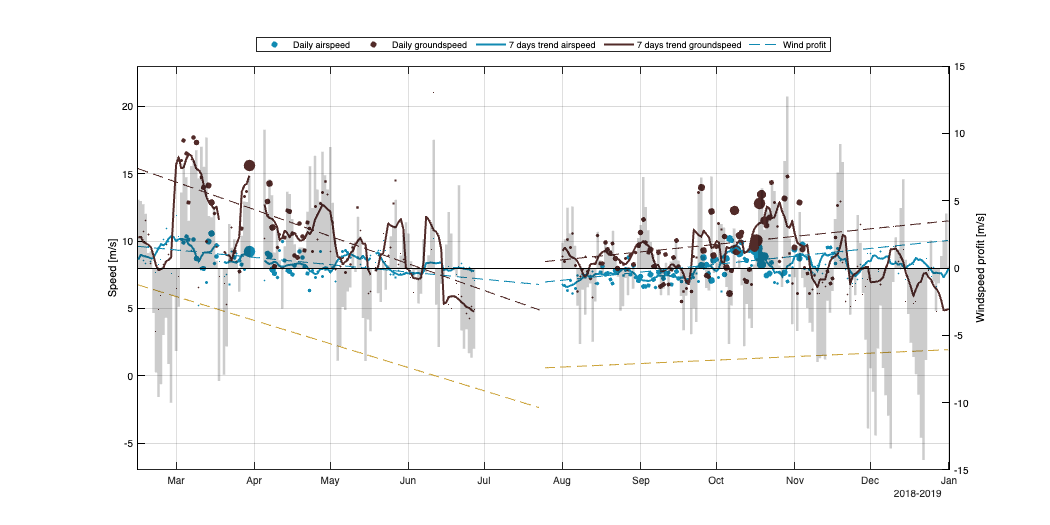

t = datetime(day_num_full,'convertfrom','datenum');

figure('position',[0 0 1200 600]); hold on; box on; axis tight; grid on;
scatter(t,mt(:,1),densd/10000,'filled')
scatter(t,mt(:,2),densd/10000,'filled')
set(gca,'ColorOrderIndex',1)
plot(t,mtm(:,1:2),'linewidth',2)
set(gca,'ColorOrderIndex',1)
id = t'<t(end/2) & ~isnan(densd) & ~isnan(mt(:,1));
fit_lm_sp = fit(datenum(t(id))'-datenum(t(1)),mt(id,1),'poly1','Weight',densd(id));
plot(t(t<t(end/2)),feval(fit_lm_sp,datenum(t(t<t(end/2)))'-datenum(t(1))),'--')
% cf = fit(datenum(t(id))'-datenum(t(1)),mt(id,2),'poly1','Weight',densd(id));
% plot(t(t<t(end/2)),feval(cf,datenum(t(t<t(end/2)))'-datenum(t(1))),'--')
fit_lm_sp2 = fit(datenum(t(id))'-datenum(t(1)),mt(id,2),'poly1','Weight',densd(id));
plot(t(t<t(end/2)),feval(fit_lm_sp2,datenum(t(t<t(end/2)))'-datenum(t(1))),'--')
fit_lm_sp3 = fit(datenum(t(id))'-datenum(t(1)),mt(id,4),'poly1','Weight',densd(id));
plot(t(t<t(end/2)),feval(fit_lm_sp3,datenum(t(t<t(end/2)))'-datenum(t(1))),'--')
set(gca,'ColorOrderIndex',1)
id = t'>t(end/2) & ~isnan(densd) & ~isnan(mt(:,1));
fit_lm_au = fit(datenum(t(id))'-datenum(t(1)),mt(id,1),'poly1','Weight',densd(id));
plot(t(t>t(end/2)),feval(fit_lm_au,datenum(t(t>t(end/2)))'-datenum(t(1))),'--')
% cf = fit(datenum(t(id))'-datenum(t(1)),mt(id,2),'poly1','Weight',densd(id));
% plot(t(t>t(end/2)),feval(cf,datenum(t(t>t(end/2)))'-datenum(t(1))),'--')
fit_lm_au2 = fit(datenum(t(id))'-datenum(t(1)),mt(id,2),'poly1','Weight',densd(id));
plot(t(t>t(end/2)),feval(fit_lm_au2,datenum(t(t>t(end/2)))'-datenum(t(1))),'--')
fit_lm_au3 = fit(datenum(t(id))'-datenum(t(1)),-mt(id,4),'poly1','Weight',densd(id));
plot(t(t>t(end/2)),feval(fit_lm_au3,datenum(t(t>t(end/2)))'-datenum(t(1))),'--')
ylim(8+[-15 15]); ylabel('Speed [m/s]')

yyaxis right;
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
bar(t(1:end/2),mt(1:end/2,4),1,'k','FaceAlpha',0.2);
bar(t(end/2:end),-mt(end/2:end,4),1,'k','FaceAlpha',0.2);
legend('Daily airspeed','Daily groundspeed','7 days trend airspeed','7 days trend groundspeed','Wind profit','Orientation','horizontal','Location','northoutside');
ylim([-15 15]); ylabel('Windspeed profit [m/s]')

fit_lm_sp_confint = confint(fit_lm_sp)*30;
fit_lm_sp_confint2 = confint(fit_lm_sp2)*30;
fit_lm_sp_confint3 = confint(fit_lm_sp3)*30;
disp(['Airspeed decreases by ' num2str(fit_lm_sp.p1*30,2) 'm/s (' num2str(fit_lm_sp_confint(1,1),2) '-' num2str(fit_lm_sp_confint(2,1),2) ') per month'])

Airspeed decreases by -0.53m/s (-0.73--0.34) per month


disp(['Groundspeed decreases by ' num2str(fit_lm_sp2.p1*30,2) 'm/s (' num2str(fit_lm_sp_confint2(1,1),2) '-' num2str(fit_lm_sp_confint2(2,1),2) ') per month'])

Groundspeed decreases by -2m/s (-2.6--1.4) per month


disp(['Windprofit decreases by ' num2str(fit_lm_sp3.p1*30,2) 'm/s (' num2str(fit_lm_sp_confint3(1,1),2) '-' num2str(fit_lm_sp_confint3(2,1),2) ') per month'])

Windprofit decreases by -1.7m/s (-2.4--1) per month


fit_lm_au_confint = confint(fit_lm_au)*30;
fit_lm_au_confint2 = confint(fit_lm_au2)*30;
fit_lm_au_confint3 = confint(fit_lm_au3)*30;
disp(['Airspeed decreases by ' num2str(fit_lm_au.p1*30,2) 'm/s (' num2str(fit_lm_au_confint(1,1),2) '-' num2str(fit_lm_au_confint(2,1),2) ') per month'])

Airspeed decreases by 0.58m/s (0.44-0.72) per month


disp(['Groundspeed decreases by ' num2str(fit_lm_au2.p1*30,2) 'm/s (' num2str(fit_lm_au_confint2(1,1),2) '-' num2str(fit_lm_au_confint2(2,1),2) ') per month'])

Groundspeed decreases by 0.57m/s (0.19-0.94) per month


disp(['Windprofit decreases by ' num2str(fit_lm_au3.p1*30,2) 'm/s (' num2str(fit_lm_au_confint3(1,1),2) '-' num2str(fit_lm_au_confint3(2,1),2) ') per month'])

Windprofit decreases by 0.25m/s (-0.34-0.85) per month


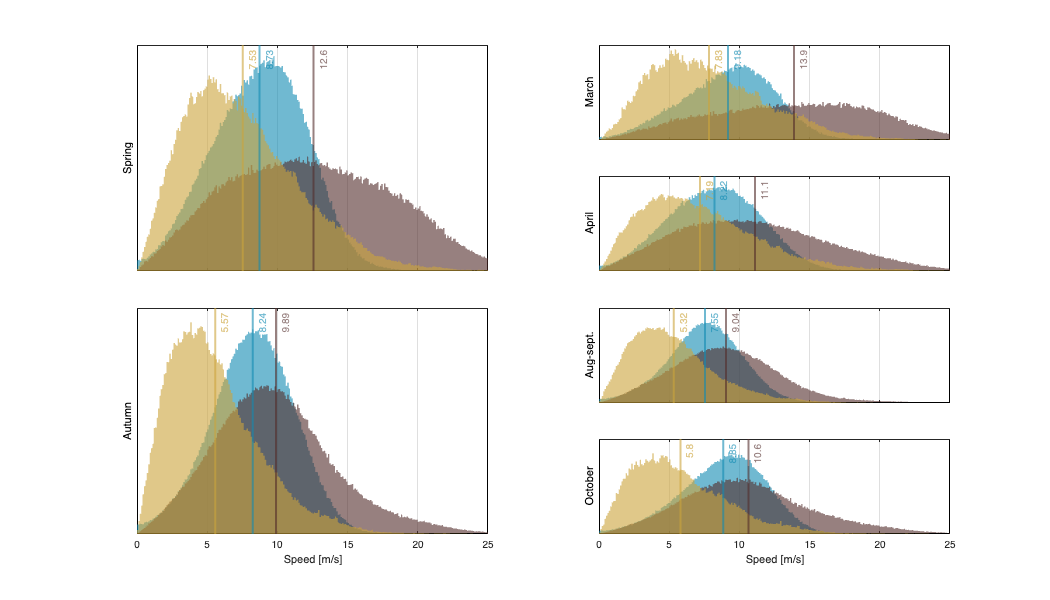

figure('position',[0 0 1400 800]);
for i_s=1:2
    subplot(4,2,[(i_s-1)*4+1 (i_s-1)*4+3]); hold on;
    [b,h,Ma,Sa] = histvdens(T.as(id_s(:,i_s)),T.dens(id_s(:,i_s)));
    tmp1 = bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
    [b,h,Mg,Sg] = histvdens(T.gs(id_s(:,i_s)),T.dens(id_s(:,i_s)));
    tmp2 = bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
    yticks([]); yticklabels(''); xlim([0 25]); ylabel(id_s_name{i_s})
    if i_s==2
        xlabel('Speed [m/s]');
    else
        xticklabels('');
    end
    yyaxis right; 
    [b,h,Mw,Sw] = histvdens(T.ws(id_s(:,i_s)),T.dens(id_s(:,i_s)));
    tmp3 = bar(b,h,1,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
%     [b,h,Mw,Sw] = histvdens(T.wsp(id_sp),T.dens(id_sp));
%     bar(b,h./sum(h),1,'FaceAlpha',0.6, 'DisplayName', ['Windprofit 45°. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
%     yyaxis left; 
%     [b,h,Ms,Ss] = histvdens(T.sd_vvp(id_s(:,i_s)),T.dens(id_s(:,i_s)));
%     tmp4 = bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['sd vvp. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
    xline(Ma,'label',num2str(Ma,3),'color',tmp1.FaceColor,'linewidth',2,'alpha',.6)
    xline(Mg,'label',num2str(Mg,3),'color',tmp2.FaceColor,'linewidth',2,'alpha',.6)
    xline(Mw,'label',num2str(Mw,3),'color',tmp3.FaceColor,'linewidth',2,'alpha',.6)
    % xline(Ms,'label',num2str(Ms,3),'color',tmp4.FaceColor,'linewidth',2,'alpha',.6)
    yticks([]); yticklabels(''); grid on
    %   xlabel([id_s_name{i} '. Bird speed [m/s]. Total nb: ' num2str(sum(T.dens(id_s(:,i)))/1000000,3) ' M']);
    box on; ax = gca; ax.YAxis(2).Color = 'k'; xlim([0 25])
end

for i_s=3:6
    subplot(4,2,2+(i_s-3)*2); hold on
    [b,h,Ma,Sa] = histvdens(T.as(id_s(:,i_s)),T.dens(id_s(:,i_s)));
    tmp1 = bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
    [b,h,Mg,Sg] = histvdens(T.gs(id_s(:,i_s)),T.dens(id_s(:,i_s)));
    tmp2 = bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
    yticks([]); yticklabels(''); xlim([0 25])
    ylabel(id_s_name{i_s})
    if i_s==6
        xlabel('Speed [m/s]');
    else
        xticklabels('');
        end
    yyaxis right; 
    [b,h,Mw,Sw] = histvdens(T.ws(id_s(:,i_s)),T.dens(id_s(:,i_s)));
    tmp3 = bar(b,h,1,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
    %legend; xlabel([id_s_name{i_s} '. Total nb: ' num2str(sum(T.dens(id_s(:,i_s)))/1000000,3) ' M']);xlim([0 30]);
%     yyaxis left; 
%     [b,h,Ms,Ss] = histvdens(T.sd_vvp(id_s(:,i_s)),T.dens(id_s(:,i_s)));
%     tmp4 = bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['sd vvp. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
    box on; ax = gca; ax.YAxis(2).Color = 'k';
    xline(Ma,'label',num2str(Ma,3),'color',tmp1.FaceColor,'linewidth',2,'alpha',.6)
    xline(Mg,'label',num2str(Mg,3),'color',tmp2.FaceColor,'linewidth',2,'alpha',.6)
    xline(Mw,'label',num2str(Mw,3),'color',tmp3.FaceColor,'linewidth',2,'alpha',.6)
    % xline(Ms,'label',num2str(Ms,3),'color',tmp4.FaceColor,'linewidth',2,'alpha',.6)
    box on; ax = gca; ax.YAxis(2).Color = 'k';
    yticks([]); yticklabels(''); grid on; xlim([0 25])
end

### Wind direction

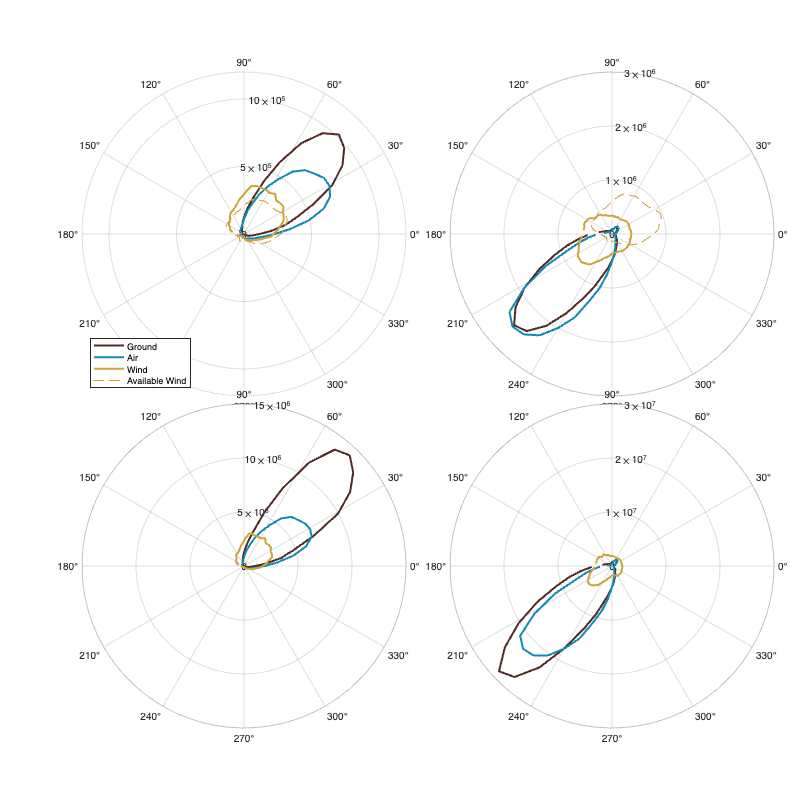

figure('position',[0 0 900 900]);
ha=tight_subplot(2,2,.01,[.09 0.09],[.08 0.01]);
axes(ha(1))
[b,h] = histCdens(T.gd(T.season==1), T.dens(T.season==1)); polarplot(b,h,'linewidth',2,'Color',colorder(2,:)); hold on;
[b,h] = histCdens(T.ad(T.season==1), T.dens(T.season==1)); polarplot(b,h,'linewidth',2,'Color',colorder(1,:))
[b,h] = histCdens(T.wd(T.season==1), T.dens(T.season==1)); polarplot(b,h,'linewidth',2,'Color',colorder(3,:))
h2 = histcounts(T.wd(T.season==1),-pi:0.1:pi); polarplot(b,h2./sum(h2)*sum(h),'--','linewidth',1,'Color',colorder(3,:))
legend('Ground','Air','Wind','Available Wind','Location','southwest')

axes(ha(2))
[b,h] = histCdens(T.gd(T.season==-1), T.dens(T.season==-1)); polarplot(b,h,'linewidth',2,'Color',colorder(2,:)); hold on;
[b,h] = histCdens(T.ad(T.season==-1), T.dens(T.season==-1)); polarplot(b,h,'linewidth',2,'Color',colorder(1,:))
[b,h] = histCdens(T.wd(T.season==-1), T.dens(T.season==-1)); polarplot(b,h,'linewidth',2,'Color',colorder(3,:))
h2 = histcounts(T.wd(T.season==1),-pi:0.1:pi); polarplot(b,h2./sum(h2)*sum(h),'--','linewidth',1,'Color',colorder(3,:))
axes(ha(3))
[b,h] = histCdens(T.gd(T.season==1), T.dens(T.season==1).*T.gs(T.season==1)); polarplot(b,h,'linewidth',2,'Color',colorder(2,:)); hold on;
[b,h] = histCdens(T.ad(T.season==1), T.dens(T.season==1).*T.as(T.season==1)); polarplot(b,h,'linewidth',2,'Color',colorder(1,:))
[b,h] = histCdens(T.wd(T.season==1), T.dens(T.season==1).*T.ws(T.season==1)); polarplot(b,h,'linewidth',2,'Color',colorder(3,:))

axes(ha(4))
[b,h] = histCdens(T.gd(T.season==-1), T.dens(T.season==-1).*T.gs(T.season==-1)); polarplot(b,h,'linewidth',2,'Color',colorder(2,:)); hold on;
[b,h] = histCdens(T.ad(T.season==-1), T.dens(T.season==-1).*T.as(T.season==-1)); polarplot(b,h,'linewidth',2,'Color',colorder(1,:))
[b,h] = histCdens(T.wd(T.season==-1), T.dens(T.season==-1).*T.ws(T.season==-1)); polarplot(b,h,'linewidth',2,'Color',colorder(3,:))

### Over space

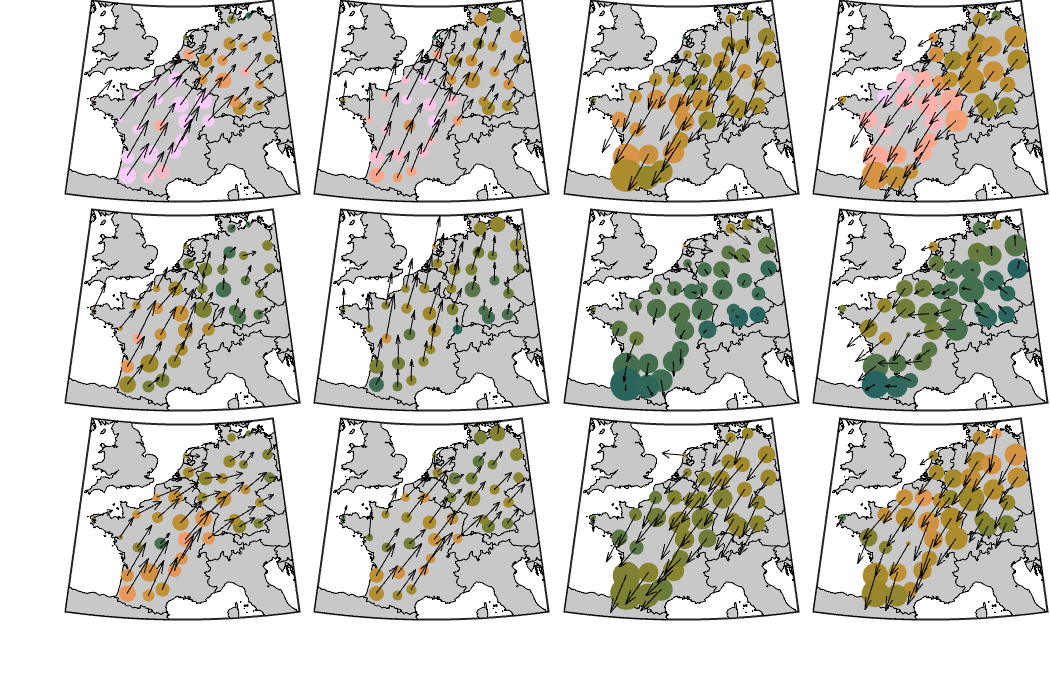

%pplot = {'w','ww','gw','aw','wp','d'};
pplot = {'g','w','a'};

figure('position',[0 0 1600 350*numel(pplot)]); 
ha=tight_subplot(numel(pplot),4,.01,[.1 0],[.06 0]); u=1;
for i_p =1:numel(pplot)
    for i_s = 1:4
        axes(ha(u)); u=u+1;
        % subplot(numel(pplot),4,4*(i_p-1)+i_s); hold on; 
        h=worldmap([floor(min(dc_lat)-1) ceil(max(dc_lat))], [floor(min(dc_lon)-1) ceil(max(dc_lon))+1]);
        setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
        %geoshow('landareas.shp', 'FaceColor', [200 200 200]./255);
        % plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
        box on; bordersm('countries', 'FaceColor', [200 200 200]./255)
        % axis([floor(min(dc_lon)-1) ceil(max(dc_lon))+1 floor(min(dc_lat)-1) ceil(max(dc_lat))])

        tmp=zeros(4,ndc);
        for i_d=1:ndc
            id = id_s(:,i_s+2)&T.r==i_d;
            w = T.dens(id) ./ sum(T.dens(id));
            tmp(1,i_d) = sum(w.*T.(pplot(i_p)+"s")(id));
            tmp(2,i_d) = sum(w.*T.(pplot(i_p)+"s")(id).*cos(T.(pplot(i_p)+"d")(id)));
            tmp(3,i_d) = sum(w.*T.(pplot(i_p)+"s")(id).*sin(T.(pplot(i_p)+"d")(id)));
            tmp(4,i_d) = nansum(T.dens(id));
        end
        tmp(1:3,tmp(1,:)==0)=nan;
        % scatterm(dc_lat(~isnan(tmp(1,:))),dc_lon(~isnan(tmp(1,:))),200,'k','filled');
        scatterm(dc_lat,dc_lon,tmp(4,:)/1000+1,tmp(1,:),'filled');
        quiverm(dc_lat,dc_lon,tmp(3,:)/5,tmp(2,:)/5,'k');
        if i_s==1
            ylabel(pplot{i_p})
        end
        if i_p==numel(pplot)
            xlabel(id_s_name{i_s+2});
        end
        caxis([0 15])
    end
end

### Air vs Ground in a**ltitude**

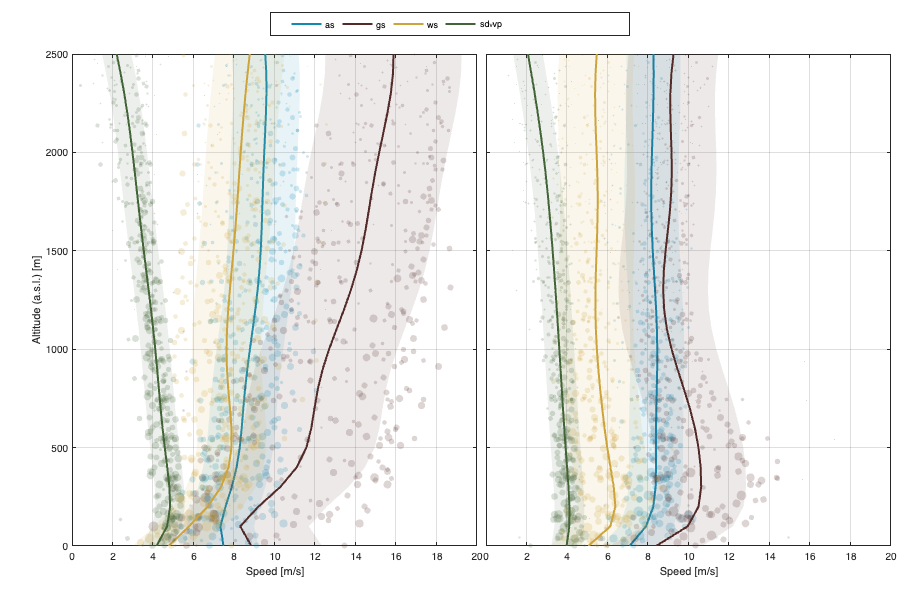

warning('off','all')
pplot = {'as','gs','ws','sd_vvp'};
x=0:100:3000;
figure('position',[0 0 900 600]);
ha=tight_subplot(1,2,.01,[.09 0.09],[.08 0.01]); u=1;
for i_s=1:2
    axes(ha(u)); u=u+1; 
    clear h
    for i_p=1:numel(pplot)
        tmp=nan(numel(dc_alt),ndc); tmp2=tmp; tmp3=tmp;
        for i_d=1:ndc
            id=T.r==i_d & id_s(:,i_s);
            if sum(id)>0
                [G,Galt]=findgroups(T.alt(id));
        
                tmp(1:numel(Galt),i_d) = splitapply(@nansum,T.dens(id), G);
                tmp2(1:numel(Galt),i_d) = splitapply(@(x) nansum(x(:,1).*x(:,2)./sum(x(:,2))), [T.(pplot{i_p})(id) T.dens(id)], G);
                tmp3(1:numel(Galt),i_d) = Galt-dc_dem(i_d);
            end
    
        end

        [p,S]=polyfit(tmp3(~isnan(tmp2)),tmp2(~isnan(tmp2)),10);

        s = (tmp(:)); s = 100*s./max(s);
        scatter(tmp2(:),tmp3(:),s,colorder(i_p,:),'filled','MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
        [y,delta] = polyval(p,x,S);
        hold on;
        fill([y+delta fliplr(y-delta)],[x fliplr(x)],colorder(i_p,:),'FaceAlpha',0.1,'EdgeColor','none')
        h(i_p)=plot(y,x,'color',colorder(i_p,:),'LineWidth',2);
    end
    xlim([0 20]); ylim([0 2500]); box on;

    if i_s==1
        ylabel('Altitude (a.s.l.) [m]')
        legend(h,pplot,'Orientation','horizontal','position',[.3 .94 .4 .04])
    else
        yticklabels('')
    end
    xlabel('Speed [m/s]'); grid on;
end

## Discussion

### Overall Airspeed vs Groundspeed

figure('position',[0 0 1000 300]);
subplot(1,2,1); hold on;
[b,h,Ma,Sa] = histvdens(T.as, T.dens);
bar(b,h,1,'FaceAlpha',0.6);
[b,h,Mg,Sg] = histvdens(T.gs, T.dens);
bar(b,h,1,'FaceAlpha',0.6);

%plot(0:30,normpdf(0:30,Mg,Sg)./max(normpdf(0:30,Mg,Sg))*max(tmp3),'-r');
%plot(0:30,normpdf(0:30,M,Sa)./max(normpdf(0:30,M,Sa))*max(tmp3),'-r');
legend( ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)])
xlabel('Bird speed [m/s]'); box on
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);
subplot(1,2,2); hold on; box on;
set(gca,'ColorOrderIndex',4)
tmp = T.gs-T.as;
[b,h] = histvdens(tmp(tmp>0), T.dens(tmp>0),-20.1:20);
bar(b,h,1,'FaceAlpha',0.6);
[b,h] = histvdens(tmp(tmp<0), T.dens(tmp<0),-20.1:20);
bar(b,h,1,'FaceAlpha',0.6);
xline(0,'k')
xlabel('Groundspeed - airspeed [m/s]')
legend(['GS>AS = ' num2str(sum(T.dens(T.gs>=T.as))./sum(T.dens)*100,2) '% of the birds'])

Histograms of airspeed and ground speed are normalized by the density of bird, that is, each bin of bird speed is multiply not by the number of occuruance in the dataset but by the sum of all bird density flying at this speed. 

(a) Bird move (i.e. groundspeed) at around 10.5 m/s (sd=5) while their air speed is actually smaller and more restricted to a speed of 8.4m/s (sd:3).

(b) There are more birds in the air (high bird density) when their ground speed is higher than their airspeed, in other term when the wind is supporting their movement. 

### Importance of Wind

M=nan(3,4); S=M;

mean and std of groudnspeed 

[~,~,M(1,1),S(1,1)] = histvdens(T.gs, T.dens);
[~,~,M(2,1),S(2,1)] = histvdens(T.gs(T.season==1), T.dens(T.season==1));
[~,~,M(3,1),S(3,1)] = histvdens(T.gs(T.season==-1), T.dens(T.season==-1));

mean and std of airspeed 

[~,~,M(1,2),S(1,2)] = histvdens(T.as, T.dens);
[~,~,M(2,2),S(2,2)] = histvdens(T.as(T.season==1), T.dens(T.season==1));
[~,~,M(3,2),S(3,2)] = histvdens(T.as(T.season==-1), T.dens(T.season==-1));

mean and std of Windspeed 

[~,~,M(1,3),S(1,3)] = histvdens(T.ws, T.dens);
[~,~,M(2,3),S(2,3)] = histvdens(T.ws(T.season==1), T.dens(T.season==1));
[~,~,M(3,3),S(3,3)] = histvdens(T.ws(T.season==-1), T.dens(T.season==-1));

mean and std of Windprofit 

Adjust the sign of wind profit for spring and autum: 

T_wsp=T.wsp; T_wsp(T.season==-1)=-T.wsp(T.season==-1);
[~,~,M(1,4),S(1,4)] = histvdens(T_wsp, T.dens);
[~,~,M(2,4),S(2,4)] = histvdens(T_wsp(T.season==1), T.dens(T.season==1));
[~,~,M(3,4),S(3,4)] = histvdens(T_wsp(T.season==-1), T.dens(T.season==-1));

Display

table({'Year-round';'Spring';'Autumn'},M(:,1), S(:,1), M(:,2), S(:,2),M(:,3), S(:,3), M(:,4), S(:,4),'VariableNames',{'Season','Mean groundspeed','Std gs','Mean airspeed','Std as','Mean Windspeed','Std ws','Mean Windprofit','Std wp'})

### Wind usage

First, I'm looking at confirming basic trend which are already known to check that all the methodolgy and dataset are correct. 

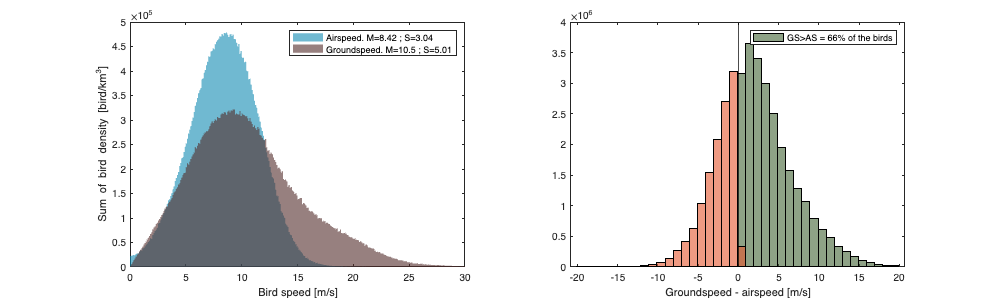

figure; hold on;
[~, id] = sort(T.dens(:)); id2 = id(T.dens(id)>5); % only keep density >5bird/km^2 for computing reason
scatter(T.as(id2),T.gs(id2),[],T.dens(id2),'filled'); axis tight equal;
plot([0 40],[0 40],'k','LineWidth',2); box on
xlabel('airspeed [m/s]'); ylabel('groundspeed [m/s]');

c=colorbar; c.Label.String='Bird density [bird/km^2]';

[tmp_GS, tmp_AS]=meshgrid(round(0:.1:25,1),round(0:.1:25,1));

[Lia,tmp_id] = ismember([round(T.gs,1), round(T.as,1)],[tmp_GS(:) tmp_AS(:)],'rows');

DENSGA=nan(size(tmp_GS));
[G,IDtmpID]=findgroups(tmp_id);
tmp = splitapply(@sum,T.dens,G);
DENSGA(IDtmpID(2:end)) = tmp(2:end);
%COUNTDENS = splitapply(@numel,T.dens,G);

figure('position',[0 0 1000 600]); hold on;
imagesc(0:.1:25,0:.1:25,DENSGA')
plot([0 25],[0 25],'--w','linewidth',2); 
axis equal tight; ylim([0 25]); xlabel('Airspeed'); ylabel('Groundspeed'); caxis([0 5500])
c=colorbar; c.Label.String='Total Density';

### Windsupport vs density

T_wsp=T.wsp; T_wsp(T.season==-1)=-T.wsp(T.season==-1);
fitobject = fit(T_wsp,T.dens,'poly6','weight',T.dens);

figure('position',[0 0 1000 600]); hold on; box on
tmp = T.dens>5; scatter(T_wsp(tmp),T.dens(tmp),T.dens(tmp)/4,T.dens(tmp),'filled');
xlim([-20 20]); plot(fitobject)

ans = 3×9 table
        Season        Mean groundspeed    Std gs    Mean airspeed    Std as    Mean Windspeed    Std ws    Mean Windprofit    Std wp
    ______________    ________________    ______    _____________    ______    ______________    ______    _______________    ______

    {'Year-round'}          10.46         5.0063       8.4177        3.0407        6.2213        3.6681        2.0248           5.12
    {'Spring'    }         12.575         5.8469       8.7285        3.2825        7.5255        4.1016        4.6029         5.0239
    {'Autumn'    }         9.7272         4.4519       8.3101        2.9448        5.7699        3.3906        1.1323          4.843


ylim([0 400]); xlim([-20 20]); xlabel('Wind support'); ylabel('Bird density')

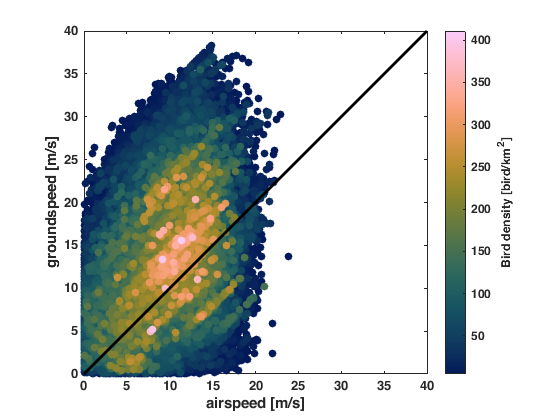

figure;
subplot(2,1,1); hold on;
[b,h,Mw,Sw] = histvdens(T_wsp(T.season==1),T.dens(T.season==1),-20:20);
bar(b,h./sum(h)/(b(2)-b(1)),1,'facecolor',id_sp_col,'FaceAlpha',0.6);
ksdensity(T_wsp(T.season==-1));
xline(Mw,'-', string(Mw));
xlim([-20 20]);box on; xlabel('Windprofit [m/s]')
legend('Used','Available'); ylabel('Spring')

subplot(2,1,2); hold on;
[b,h,Mw,Sw] = histvdens(T_wsp(T.season==-1),T.dens(T.season==-1),-20:20);
bar(b,h./sum(h)/(b(2)-b(1)),1,'facecolor',id_au_col,'FaceAlpha',0.6);
ksdensity(T_wsp(T.season==1));xline(Mw,'-', string(Mw));
xlim([-20 20]); box on; xlabel('Windprofit [m/s]'); ylabel('Autumn')

figure('position',[0 0 800 400]); hold on;
scatter(t(1:end/2),mt(1:end/2,4) ./ mt(1:end/2,2),densd(1:end/2)/10000,id_sp_col,'filled')
scatter(t(end/2:end),-mt(end/2:end,4) ./ mt(end/2:end,2),densd(end/2:end)/10000,id_au_col,'filled')
ylim([-1 1]); ylabel('Windprofit / Groundspeed'); grid on; box ;

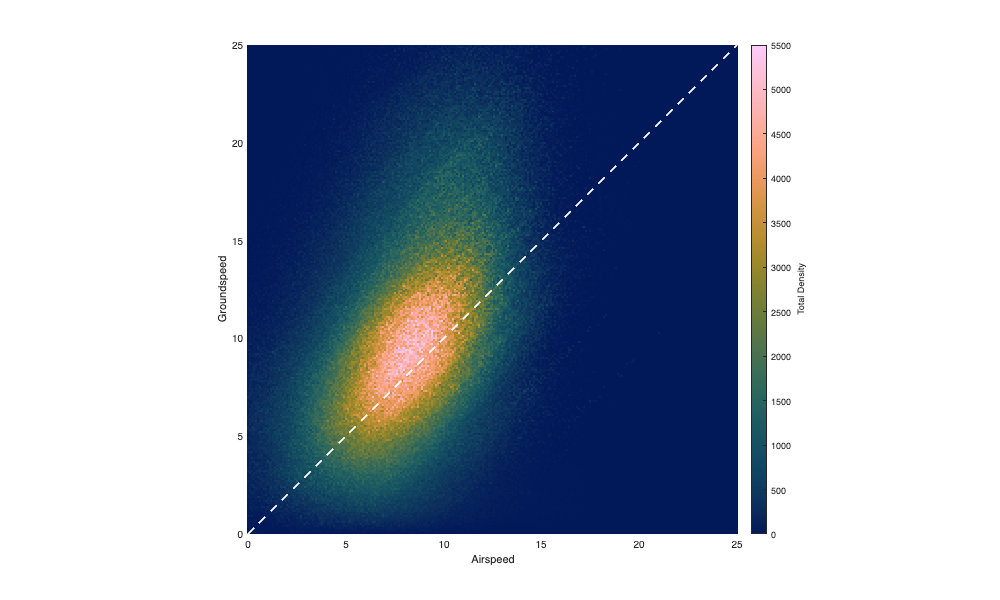

figure('position',[0 0 1000 600]);
subplot(2,1,1); hold on;
[b,h,Mw,Sw] = histvdens(T.sd_vvp(T.season==-1),T.dens(T.season==-1),0:.1:8);
bar(b,h./sum(h)/(b(2)-b(1)),1,'facecolor',id_sp_col,'FaceAlpha',0.6);
[b,h,Mw,Sw] = histvdens(T.sd_vvp(T.season==1),T.dens(T.season==1),0:.1:8);

bar(b,h./sum(h)/(b(2)-b(1)),1,'facecolor',id_au_col,'FaceAlpha',0.6);
xlim([0 7]); box on;
subplot(2,1,2);hold on;
scatter(t(1:end/2)',mt(1:end/2,5),densd(1:end/2)/10000,id_sp_col,'filled')
scatter(t(end/2:end)',mt(end/2:end,5),densd(end/2:end)/10000,id_au_col,'filled')
plot(t(1:end/2),mtm(1:end/2,5),'linewidth',2,'color',id_sp_col)
plot(t(end/2:end),mtm(end/2:end,5),'linewidth',2,'color',id_au_col)
ylabel('SDVVP'); grid on; box on;

### Time

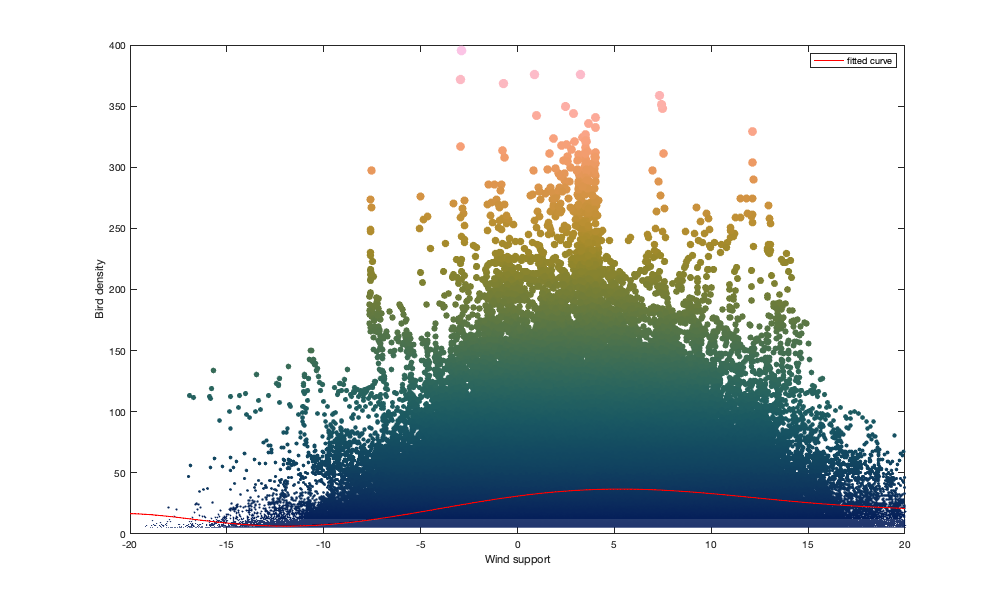

clear bg hg Mg Sg ba ha Ma Sa
[bg(1,:),hg(1,:),Mg(1),Sg(1)] = histvdens(T.gs(id_s(:,1)),T.dens(id_s(:,1)));

[ba(1,:),ha(1,:),Ma(1),Sa(1)] = histvdens(T.as(id_s(:,1)),T.dens(id_s(:,1)));
[bg(2,:),hg(2,:),Mg(2),Sg(2)] = histvdens(T.gs(id_s(:,2)),T.dens(id_s(:,2)));
[ba(2,:),ha(2,:),Ma(2),Sa(2)] = histvdens(T.as(id_s(:,2)),T.dens(id_s(:,2)));

tUs =table({'Spring';'Autumn'},Mg',Ma','VariableNames',{'Season','Groundspeed','Airspeed'});
tUs = [tUs; table({'Ratio'}, tUs{1,2}./tUs{2,2}, tUs{1,3}./tUs{2,3},'VariableNames',{'Season','Groundspeed','Airspeed'})];
tUs.ratio = tUs.Groundspeed./tUs.Airspeed

P(air-autum < air-spring)

1-sum(cumsum(ha(1,:))/sum(ha(1,:)).*ha(2,:)./sum(ha(2,:)))
1-sum(cumsum(hg(1,:))/sum(hg(1,:)).*hg(2,:)./sum(hg(2,:)))

Radar per radar

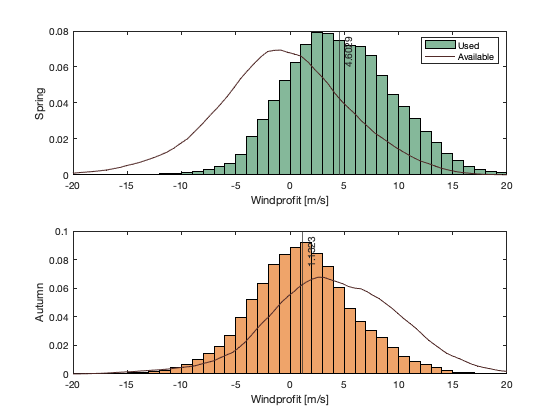

clear Mg Ma Sg Sa
for i_r=1:max(T.r)
    id = id_s(:,1) & T.r==i_r;
    [~,~,Mg(i_r,1),Sg(i_r,1)] = histvdens(T.gs(id),T.dens(id));
    [~,~,Ma(i_r,1),Sa(i_r,1)] = histvdens(T.as(id),T.dens(id));
    nb(i_r,1) = sum(T.dens(id));

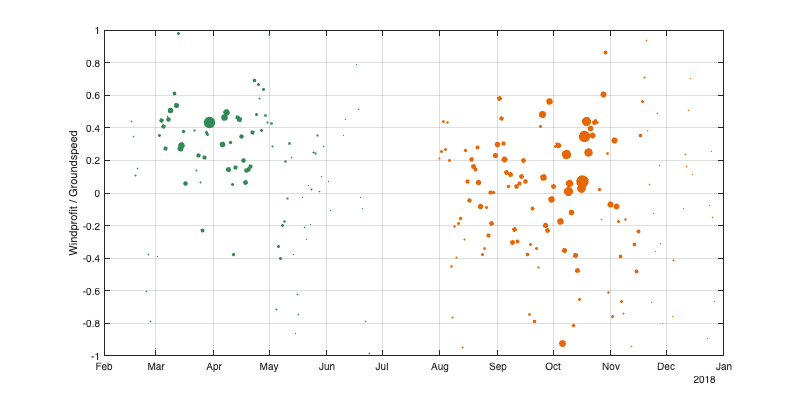

    id = id_s(:,2) & T.r==i_r;
    [~,~,Mg(i_r,2),Sg(i_r,2)] = histvdens(T.gs(id),T.dens(id));
    [~,~,Ma(i_r,2),Sa(i_r,2)] = histvdens(T.as(id),T.dens(id));
    nb(i_r,2) = sum(T.dens(id));
end


figure;  hold on; box on
plot([.6 1.5],[.6 1.5],'--k')
xline(1,'--k'); yline(1,'--k')
dc_lat = [dc.lat];
s1=scatter(Ma(id_de,1)./Ma(id_de,2),Mg(id_de,1)./Mg(id_de,2),mean(nb(id_de,:),2)/2000,dc_lat(id_de),'filled','o');
s2=scatter(Ma(id_fr,1)./Ma(id_fr,2),Mg(id_fr,1)./Mg(id_fr,2),mean(nb(id_fr,:),2)/2000,dc_lat(id_fr),'filled','s');
s3=scatter(Ma(~id_fr&~id_de,1)./Ma(~id_fr&~id_de,2),Mg(~id_fr&~id_de,1)./Mg(~id_fr&~id_de,2),mean(nb(~id_fr&~id_de,:),2)/2000,dc_lat(~id_fr&~id_de)','filled','s');
axis equal square;
xlabel('Airspeed ratio (Spring/Autum)')
ylabel('Groundspeed ratio (Spring/Autum)')
c=colorbar; c.Label.String='Lattitude';
legend([s1 s2 s3] ,'DE Radar (size=number of birds)','FR Radar','BL NL Radar')

### Comparison with other study

#### Horton et al. (2016)

This figure reproduces Figure .. of Horton et al. 2016 ([https://doi.org/10.1642/AUK-16-105.1](https://doi.org/10.1642/AUK-16-105.1)).

The difference of processing includes:

- 3 autumn season, 2 spring season (2013-2015). March 1 to June 15. August 1 to November 15

- Same: civil twilight, discard when precipication 

- eliminate when VAD RMSE is >5 (poor fit) and <1 (insects).

- keep up to 2km altitude.

- "For purposes of averaging we weighted all measures following the distribution of the vertical profile of reflectivity (dBZ)". Not sure what this means. Weighted by reflecitivtiy or reflectivty normalized over verctical profile?

- airspeeds less than 5 m/s

- Weight wind direction by reflecitivity x windspeed

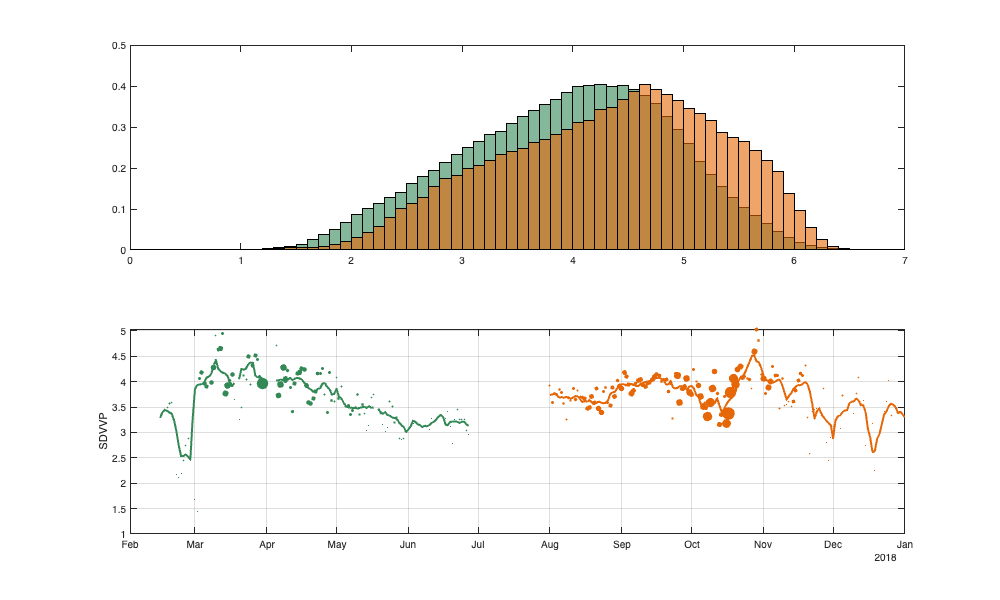

figure('position',[0 0 400 1000]);


subplot(3,1,1); hold on;
[b,h,Mg,Sg] = histvdens(T.gs(id_sp),T.dens(id_sp),0:1:30);
bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Spring. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',[.05 .05 .05],'EdgeAlpha',0);
[b,h,Mg,Sg] = histvdens(T.gs(id_au),T.dens(id_au),0:1:30);
bar(b,h./sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Autumn. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',[.5 .5 .5],'EdgeAlpha',0);
legend; xlabel(['Groundspeed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(T.dens(id_sp))))/1000000,3) ' M']);
ylabel('Sum of bird T.density [bird/km^3]'); xlim([0 30]);

subplot(3,1,2); hold on;
[b,h,Ma,Sa] = histvdens(T.sd_vvp(id_sp),T.dens(id_sp),1.5:0.2:10);
bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Spring. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.05 .05 .05],'EdgeAlpha',0);
[b,h,Ma,Sa] = histvdens(T.sd_vvp(id_au),T.dens(id_au),1.5:0.2:10);
bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Autumn. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.5 .5 .5],'EdgeAlpha',0);
legend; xlabel(['Spectrum width [m/s]. Total nb: ' num2str(nansum(nansum(nansum(T.dens(id_au))))/1000000,3) ' M']);
ylabel('Sum of bird T.density [bird/km^3]'); xlim([1.5 6]);

subplot(3,1,3); hold on;
[b,h,Ma,Sa] = histvdens(T.as(id_sp),T.dens(id_sp),0:1:20);
bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Spring. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.05 .05 .05],'EdgeAlpha',0);
[b,h,Ma,Sa] = histvdens(T.as(id_au),T.dens(id_au),0:1:20);

tUs = 3×4 table
      Season      Groundspeed    Airspeed    ratio 
    __________    ___________    ________    ______

    {'Spring'}      12.575        8.7285     1.4407
    {'Autumn'}      9.8938        8.2386     1.2009
    {'Ratio' }       1.271        1.0595     1.1997


bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Autumn. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.5 .5 .5],'EdgeAlpha',0);
legend; xlabel(['Airspeed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(T.dens(id_au))))/1000000,3) ' M']);

ans = 0.5411

ylabel('Sum of bird T.density [bird/km^3]'); xlim([5 20]);

ans = 0.6336

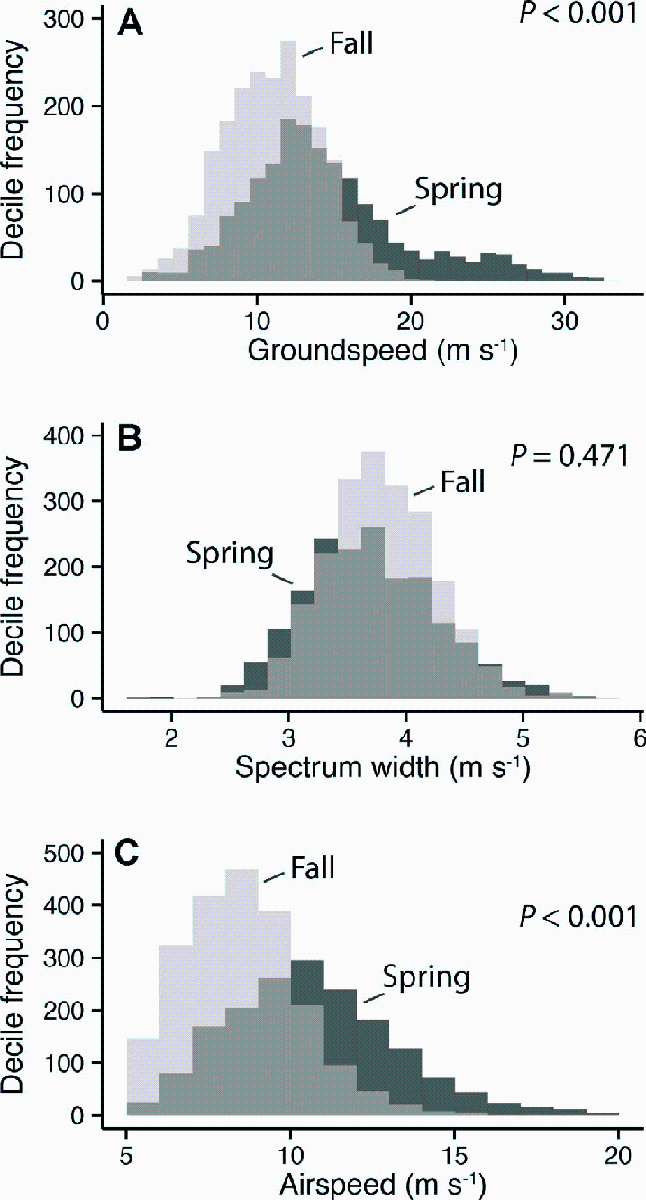

tHorton = table({'Spring';'Autumn'},[14.7; 10.6],[10.6; 8.3],'VariableNames',{'Season','Groundspeed','Airspeed'});
tHorton = [tHorton; table({'Ratio'}, tHorton{1,2}./tHorton{2,2}, tHorton{1,3}./tHorton{2,3},'VariableNames',{'Season','Groundspeed','Airspeed'})];
tHorton.ratio = tHorton.Groundspeed./tHorton.Airspeed

Changing the date to the same as Horton

id_spH = T.time>=datenum('1-Mar-2018')&T.time<=datenum('15-June-2018');
id_auH = T.time>=datenum('1-Aug-2018')&T.time<=datenum('15-Nov-2018');

[bg(1,:),hg(1,:),Mg(1),Sg(1)] = histvdens(T.gs(id_spH),T.dens(id_spH));
[ba(1,:),ha(1,:),Ma(1),Sa(1)] = histvdens(T.as(id_spH),T.dens(id_spH));
[bg(2,:),hg(2,:),Mg(2),Sg(2)] = histvdens(T.gs(id_auH),T.dens(id_auH));
[ba(2,:),ha(2,:),Ma(2),Sa(2)] = histvdens(T.as(id_auH),T.dens(id_auH));

tUs =table({'Spring';'Autumn'},Mg',Ma','VariableNames',{'Season','Groundspeed','Airspeed'});
tUs = [tUs; table({'Ratio'}, tUs{1,2}./tUs{2,2}, tUs{1,3}./tUs{2,3},'VariableNames',{'Season','Groundspeed','Airspeed'})];
tUs.ratio = tUs.Groundspeed./tUs.Airspeed

- Generally similar range of value for airpseed and groundspeed (8-14m/s)

- Similar range of ratio (1-1.4).

- Same ratio of groundspeed faster than airspeed (1.4 in Spring and 1.2 in Autumn)

- Same ratio of spring faster than autumn for groundspeed (1.27-1.38)

- But different ratio for airpseed 1.27 for them and 1.06 for us! 

What happen if we filter the airspeed with 5 m/s

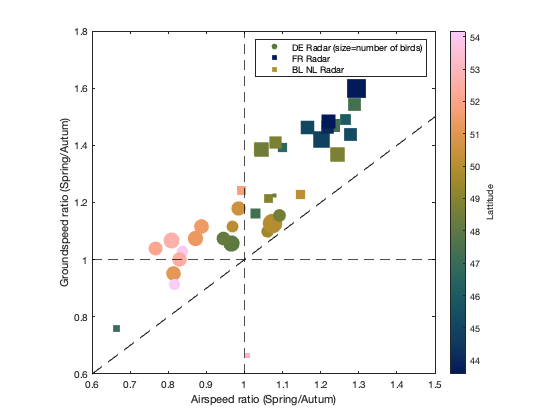

id_spH2 = id_spH & T.as>5 & T.sd_vvp>1 & T.sd_vvp<5 & T.alt <= 2000 ;

id_auH2 = id_au & T.as>5 & T.sd_vvp>1 & T.sd_vvp<5 &T.alt <= 2000;

[bg(1,:),hg(1,:),Mg(1),Sg(1)] = histvdens(T.gs(id_spH2),T.dens(id_spH2));
[ba(1,:),ha(1,:),Ma(1),Sa(1)] = histvdens(T.as(id_spH2),T.dens(id_spH2));
[bg(2,:),hg(2,:),Mg(2),Sg(2)] = histvdens(T.gs(id_auH2),T.dens(id_auH2));
[ba(2,:),ha(2,:),Ma(2),Sa(2)] = histvdens(T.as(id_auH2),T.dens(id_auH2));

tUs =table({'Spring';'Autumn'},Mg',Ma','VariableNames',{'Season','Groundspeed','Airspeed'});
tUs = [tUs; table({'Ratio'}, tUs{1,2}./tUs{2,2}, tUs{1,3}./tUs{2,3},'VariableNames',{'Season','Groundspeed','Airspeed'})];
tUs.ratio = tUs.Groundspeed./tUs.Airspeed

The filtering is not really explaning much of this difference between their result and ours... 

#### Kemp et al. (2011)

 Kemp, M.U.; Shamoun-Baranes, J.; Van Gasteren, H.; Bouten, W.; Van Loon, E.E. Can wind help explain seasonal differences in avian migration speed? *J. Avian Biol.* **2010**, *41*, 672–677. DOI:[10.1111/j.1600-048X.2010.05053.x](http://doi.org/10.1111/j.1600-048X.2010.05053.x)

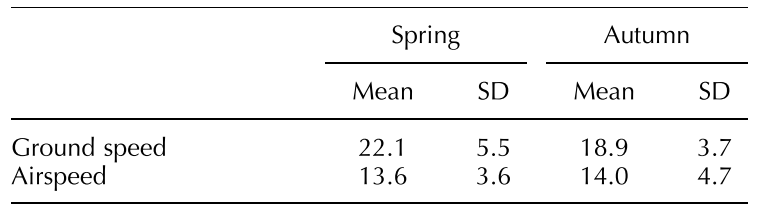

Comparing that to all our radar

id_spK = T.time>datenum('1-Feb-2018') & T.time<datenum('1-June-2018');
id_auK = T.time>datenum('1-August-2018') & T.time<datenum('1-Dec-2018');

[bg(1,:),hg(1,:),Mg(1),Sg(1)] = histvdens(T.gs(id_spK),T.dens(id_spK));
[ba(1,:),ha(1,:),Ma(1),Sa(1)] = histvdens(T.as(id_spK),T.dens(id_spK));
[bg(2,:),hg(2,:),Mg(2),Sg(2)] = histvdens(T.gs(id_auK),T.dens(id_auK));
[ba(2,:),ha(2,:),Ma(2),Sa(2)] = histvdens(T.as(id_auK),T.dens(id_auK));

tUs =table({'Spring';'Autumn'},Mg',Ma','VariableNames',{'Season','Groundspeed','Airspeed'});
tUs = [tUs; table({'Ratio'}, tUs{1,2}./tUs{2,2}, tUs{1,3}./tUs{2,3},'VariableNames',{'Season','Groundspeed','Airspeed'})];
tUs.ratio = tUs.Groundspeed./tUs.Airspeed

Only Dutch Radar

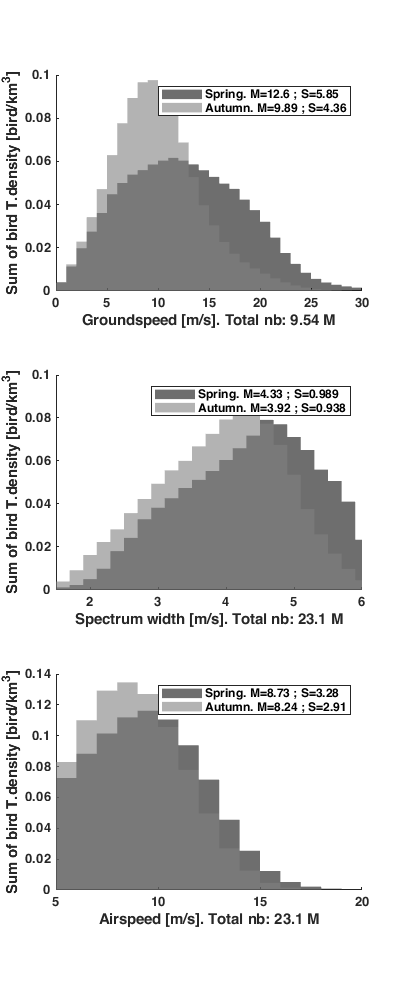

id_spK = T.time>datenum('1-Feb-2018') & T.time<datenum('1-June-2018') & ismember(T.r,find(contains(dc_name,'nl')));
id_auK = T.time>datenum('1-August-2018') & T.time<datenum('1-Dec-2018') & ismember(T.r,find(contains(dc_name,'nl')));

[bg(1,:),hg(1,:),Mg(1),Sg(1)] = histvdens(T.gs(id_spK),T.dens(id_spK));
[ba(1,:),ha(1,:),Ma(1),Sa(1)] = histvdens(T.as(id_spK),T.dens(id_spK));
[bg(2,:),hg(2,:),Mg(2),Sg(2)] = histvdens(T.gs(id_auK),T.dens(id_auK));
[ba(2,:),ha(2,:),Ma(2),Sa(2)] = histvdens(T.as(id_auK),T.dens(id_auK));

tUs =table({'Spring';'Autumn'},Mg',Ma','VariableNames',{'Season','Groundspeed','Airspeed'});
tUs = [tUs; table({'Ratio'}, tUs{1,2}./tUs{2,2}, tUs{1,3}./tUs{2,3},'VariableNames',{'Season','Groundspeed','Airspeed'})];

tUs.ratio = tUs.Groundspeed./tUs.Airspeed

- Speed much smaller for us, but similar variance (tracking vs radar?)

- Ratio relatively similar: Groundspeed 20-60% faster than airspeed (more for Spring than Autumn)

- Groundspeed 17% faster in Spring than Autumn (27% for us)

- Airspeed 3% slower in spring than autumn (+5% fo us)

#### Karlsson (2012) & Karlsson (2011)

 Karlsson, H.; Nilsson, C.; Bäckman, J.; Alerstam, T. Nocturnal passerine migration without tailwind assistance. *Ibis (Lond. 1859).* **2011**, *153*, 485–493.

 Karlsson, H.; Nilsson, C.; Bäckman, J.; Alerstam, T. Nocturnal passerine migrants fly faster in spring than in autumn: A test of the time minimization hypothesis. *Anim. Behav.* **2012**, *83*, 87–93.

tK=table({'Spring Lund';'Autumn Lund';'Spring Abisko';'Autumn Abisko'},[12.7;10.5;11.3;10.2],[4.2;4.1;4.9;3.3],[11.9;10.5;11.5;9.5],[2.4;2.3;2.5;2.1],[1183;512;827;566],'VariableNames',{'Season','Groundspeed','Grounsdpeed_sd','Airspeed', 'Airspeed_sd','n'});
%[tK; table({'Ratio Lund', 'Ratio Abiska'}, tK.Groundspeed([1 3])./tK.Groundspeed([2 4]), tK.Airspeed([1 3])./tK.Airspeed([2 4]),'VariableNames',{'Season','Groundspeed','Airspeed'})]
tK.ratio = tK.Groundspeed./tK.Airspeed

tHorton = 3×4 table
      Season      Groundspeed    Airspeed    ratio 
    __________    ___________    ________    ______

    {'Spring'}        14.7          10.6     1.3868
    {'Autumn'}        10.6           8.3     1.2771
    {'Ratio' }      1.3868        1.2771     1.0859


% tt = (t{1,4}-t{2,4})/sqrt( t{1,5}^2/t{1,6} + t{2,5}^2/t{2,6} )
% nu = ( t{1,5}^2/t{1,6} + t{2,5}^2/t{2,6} )^2 / ( (t{1,5}^2/t{1,6})^2/(t{1,6}-1) + (t{2,5}^2/t{2,6})^2/(t{2,6}-1) )
% p = 1-tcdf(tt,nu)

Ours

id_spKa = T.time>datenum('24-April-2018') & T.time<datenum('10-June-2018');
id_auKa = T.time>datenum('1-August-2018') & T.time<datenum('1-Sep-2018');

[bg(1,:),hg(1,:),Mg(1),Sg(1)] = histvdens(T.gs(id_spKa),T.dens(id_spKa));
[ba(1,:),ha(1,:),Ma(1),Sa(1)] = histvdens(T.as(id_spKa),T.dens(id_spKa));
[bg(2,:),hg(2,:),Mg(2),Sg(2)] = histvdens(T.gs(id_auKa),T.dens(id_auKa));
[ba(2,:),ha(2,:),Ma(2),Sa(2)] = histvdens(T.as(id_auKa),T.dens(id_auKa));

tUs =table({'Spring';'Autumn'},Mg',Ma','VariableNames',{'Season','Groundspeed','Airspeed'});
tUs = [tUs; table({'Ratio'}, tUs{1,2}./tUs{2,2}, tUs{1,3}./tUs{2,3},'VariableNames',{'Season','Groundspeed','Airspeed'})];

tUs = 3×4 table
      Season      Groundspeed    Airspeed    ratio 
    __________    ___________    ________    ______

    {'Spring'}      12.223        8.7023     1.4046
    {'Autumn'}      9.8322        8.2861     1.1866
    {'Ratio' }      1.2432        1.0502     1.1837


tUs.ratio = tUs.Groundspeed./tUs.Airspeed

#### Birdscan

Load data fro Sempach 2018

load('../2018/comparison_Birdscan/BS/Sempach_2018_cleaned')

Only keep data with groundspeed

BS(isnan(BS.groundspeed),:)=[];

and with high probability of being passerine

% BS.p_bird = BS.p_unidbird+BS.p_passer+BS.p_wader+BS.p_lsb;
% BS(BS.p_bird<0.7,:)=[];
BS(BS.p_passer<0.7,:)=[];
%BS = removevars(BS,{'p_unidbird','p_passer','p_unidbird','p_wader','p_lsb','p_bird'});

Filter based on some radar parameters

BS.s=2*BS.height.*tand(BS.theta/2);
BS.tau=BS.s./abs(BS.groundspeed);
mintau = 2;
maxtau = 60;
BS(BS.tau > maxtau | BS.tau < mintau,:)=[];

tUs = 3×4 table
      Season      Groundspeed    Airspeed    ratio 
    __________    ___________    ________    ______

    {'Spring'}      13.167        9.7942     1.3443
    {'Autumn'}      10.529        9.1962     1.1449
    {'Ratio' }      1.2505         1.065     1.1742


ans =     1.0404    1.0130
    1.0000    1.0000


and altitude 

alt = 540;
maxalt = 500;
minalt = 600-alt;
BS(BS.height > maxalt | BS.height < minalt,:)=[];

BS.airspeed=BS.groundspeed-BS.windspeed;
BS.windsupport = cosd(45)*real(BS.windspeed) + sind(45)*imag(BS.windspeed);

BS.season=zeros(size(BS.airspeed));
BS.season(BS.time_string>datetime('1-Mar-2018') & BS.time_string<datetime('1-April-2018'))=1;
BS.season(BS.time_string>datetime('1-April-2018') & BS.time_string<datetime('1-May-2018'))=2;
BS.season(BS.time_string>datetime('1-August-2018') & BS.time_string<datetime('1-Oct-2018'))=3;
BS.season(BS.time_string>datetime('1-Oct-2018') & BS.time_string<datetime('1-Nov-2018'))=4;

tUs = 3×4 table
      Season      Groundspeed    Airspeed    ratio 
    __________    ___________    ________    ______

    {'Spring'}      12.164        8.7214     1.3947
    {'Autumn'}       9.809        8.2943     1.1826
    {'Ratio' }      1.2401        1.0515     1.1794


[G_day,day_num]=findgroups(datenum(dateshift(BS.time_string,'start','day','nearest')));    
day_num_full = min(day_num):max(day_num);
[~,Locb] = ismember(day_num,day_num_full);

densd = nan(numel(day_num_full),1);
densd(Locb) = splitapply(@sum,ones(size(G_day)),G_day);
mt=nan(numel(day_num_full),5);
mt(Locb,1) = abs(splitapply(@nanmean,BS.airspeed,G_day));
mt(Locb,2) = abs(splitapply(@nanmean,BS.groundspeed,G_day));
mt(Locb,3) = abs(splitapply(@nanmean,BS.windspeed,G_day));
mt(Locb,4) = splitapply(@nanmean,BS.windsupport,G_day);
mtm = movmean(mt.*densd,7,'omitnan') ./ movmean(densd,7,'omitnan');

tUs = 3×4 table
      Season      Groundspeed    Airspeed    ratio 
    __________    ___________    ________    ______

    {'Spring'}      9.9961        8.4631     1.1811
    {'Autumn'}      8.8452        8.6385     1.0239
    {'Ratio' }      1.1301        0.9797     1.1535


mtm(isnan(densd),:)=nan;

t = datetime(day_num_full,'convertfrom','datenum');
figure('position',[0 0 1200 600]); 
%subplot(3,1,[1 2]);

tK = 4×7 table
         Season          Groundspeed    Grounsdpeed_sd    Airspeed    Airspeed_sd     n       ratio 
    _________________    ___________    ______________    ________    ___________    ____    _______

    {'Spring Lund'  }       12.7             4.2            11.9          2.4        1183     1.0672
    {'Autumn Lund'  }       10.5             4.1            10.5          2.3         512          1
    {'Spring Abisko'}       11.3             4.9            11.5          2.5         827    0.98261
    {'Autumn Abisko'}       10.2             3.3             9.5          2.1         566     1.0737


hold on;
scatter(t,mt(:,1),densd/10,'filled')
scatter(t,mt(:,2),densd/10,'filled')
set(gca, 'ColorOrder', circshift(get(gca, 'ColorOrder'), 2))
plot(t,mtm(:,1:2),'linewidth',2)
% scatter(t,mt(:,3),densd/10000,'filled')
box on; axis tight; ylim(8+[-15 15]); 
ylabel('Speed [m/s]')
yyaxis right;
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
% subplot(3,1,3); 
bar(t(1:end/2),mt(1:end/2,4),1,'k','FaceAlpha',0.2);
bar(t((end/2):end),-mt(end/2:end,4),1,'k','FaceAlpha',0.2);
legend('Daily airspeed','Daily groundspeed','7 days trend airspeed','7 days trend groundspeed','Wind profit','Orientation','horizontal','Location','northoutside');
box on; ylim([-15 15]); grid on

tUs = 3×4 table
      Season      Groundspeed    Airspeed    ratio 
    __________    ___________    ________    ______

    {'Spring'}      10.328        8.3158      1.242
    {'Autumn'}      8.8117         7.496     1.1755
    {'Ratio' }      1.1721        1.1094     1.0565


ylabel('Windspeed profit [m/s]')

figure('position',[0 0 1400 800]);
for i_s=1:2
    subplot(1,2,i_s); hold on;
    if i_s==1
        id = BS.season==1 | BS.season==2;
    else
        id = BS.season==3 | BS.season==4;
    end
    histogram(abs(BS.airspeed(id)))
    histogram(abs(BS.groundspeed(id)))
    legend({['Airspeed. M=' num2str(mean(abs(BS.airspeed(id))),3) ' ; S=' num2str(std(abs(BS.airspeed(id))),3)],['Groundspeed. M=' num2str(mean(abs(BS.groundspeed(id))),3) ' ; S=' num2str(std(abs(BS.groundspeed(id))),3)], });
    yticks([]); yticklabels(''); xlim([0 50]); %ylabel(id_s_name{i_s})
end

1-sum(cumsum(ha(1,:))/sum(ha(1,:)).*ha(2,:)./sum(ha(2,:)))
1-sum(cumsum(hg(1,:))/sum(hg(1,:)).*hg(2,:)./sum(hg(2,:)))
mean(abs(BS.airspeed(BS.season==1 | BS.season==2)))/mean(abs(BS.airspeed(BS.season==3 | BS.season==4)))
mean(abs(BS.groundspeed(BS.season==1 | BS.season==2)))/mean(abs(BS.groundspeed(BS.season==3 | BS.season==4)))

#### Superfledermaus

Load and filter data

SF = readtable('../2018/comparison_Birdscan/SF/Track.csv');
SF.Code = categorical(SF.Code);
SF=SF(SF.FieldClass==4,:);

SF.ground = SF.Vg/100 .* exp( mod(-deg2rad(SF.Rg)+90,360)*1i );
SF.wind   = SF.Vw/100 .* exp( mod(-deg2rad(SF.Rw)+90,360)*1i );
SF.air    = SF.Va/100 .* exp( mod(-deg2rad(SF.Ra)+90,360)*1i ); 
SF.windsupport = cosd(45)*real(SF.wind) + sind(45)*imag(SF.wind);
SF(isnan(SF.ground)|isnan(SF.air),:)=[];

Compute season

SF.season=day(SF.Date,'dayofyear')>365/2;

Visualize project vs count

groupsummary(SF,'Code')

All together

figure;
for i_s=1:2
    subplot(1,2,i_s); hold on;
    id = SF.season==i_s-1;
    
    histogram(abs(SF.ground(id)))
    histogram(abs(SF.air(id)))
    legend({['Groundspeed. M=' num2str(nanmean(abs(SF.ground(id))),3) ' ; S=' num2str(nanstd(abs(SF.ground(id))),3)],['Airspeed. M=' num2str(nanmean(abs(SF.air(id))),3) ' ; S=' num2str(nanstd(abs(SF.air(id))),3)] });
    yticks([]); yticklabels(''); xlim([0 50]); ylabel(id_s_name{i_s})
end

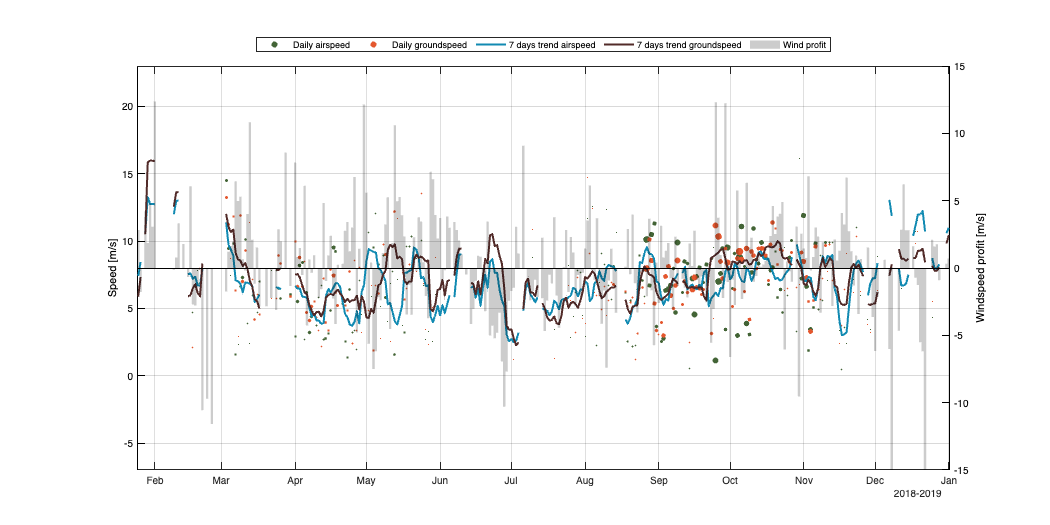

clear r
ccode={'A91', 'A92';'B96', 'B97';'D03', 'D04';'F09', 'F10';'M96', 'M97';'S91', 'S92'};
cplace={'Arava 1991/92','Mallorca 1996/97', 'Ouadane 2003/04', 'Fehmarn 2009/10','Malaga 1996/97','Sede Boqer 1991/92'};
for i_c=1:size(ccode,1)
    id = SF.Code==ccode(i_c,1) | SF.Code==ccode(i_c,2) & SF.season;
    r(i_c,1,1)=nanmean(abs(SF.ground(id)));
    r(i_c,2,1)=nanmean(abs(SF.air(id)));
    r(i_c,3,1)=sum(id);
    r(i_c,4,1)=nanstd(abs(SF.ground(id)));
    r(i_c,5,1)=nanstd(abs(SF.air(id)));
    id = SF.Code==ccode(i_c,1) | SF.Code==ccode(i_c,2) & ~SF.season;
    r(i_c,1,2)=nanmean(abs(SF.ground(id)));
    r(i_c,2,2)=nanmean(abs(SF.air(id)));
    r(i_c,3,2)=sum(id);
    r(i_c,4,2)=nanstd(abs(SF.ground(id)));
    r(i_c,5,2)=nanstd(abs(SF.air(id)));
end

% num2str(r(:,1,2),3) +" (" +num2str(r(:,4,2),2) +")"
% num2str(r(:,1,1),3) +" (" +num2str(r(:,4,1),2) +")"
% num2str(r(:,1,2)./r(:,1,1),3)
% num2str(r(:,2,2),3) +" (" +num2str(r(:,5,2),2) +")"
% num2str(r(:,2,1),3) +" (" +num2str(r(:,5,1),2) +")"

% num2str(r(:,2,2)./r(:,2,1),3)
% 
% 
% num2str(nanmean(abs(SF.ground(~SF.season))),3)
% num2str(nanmean(abs(SF.ground(SF.season))),3)
% num2str(nanmean(abs(SF.air(~SF.season))),3)
% num2str(nanmean(abs(SF.air(SF.season))),3)

Time variation

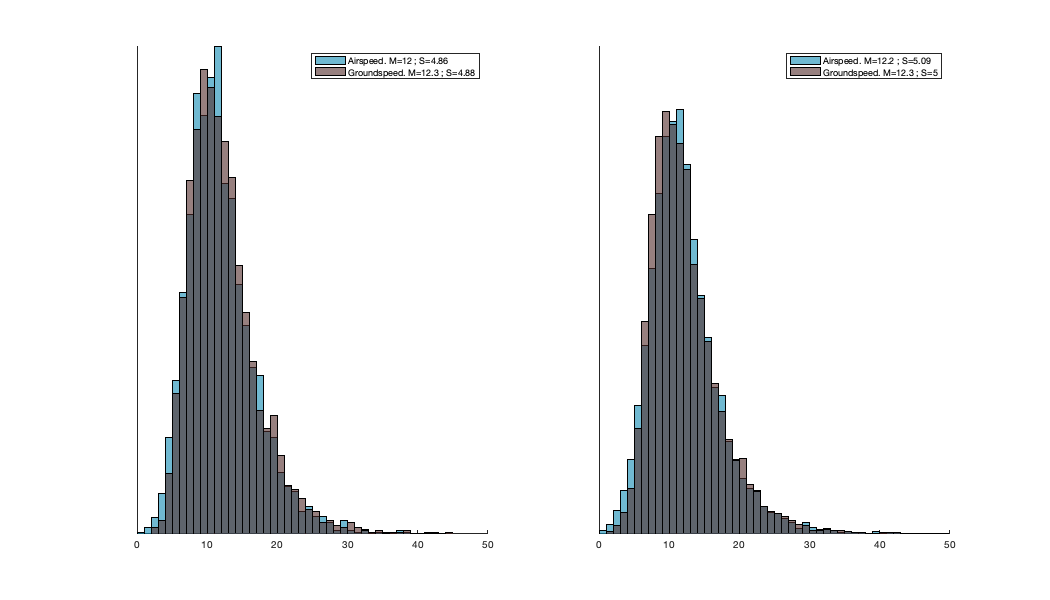

%SF.Date=SF.Date-years((year(SF.Date)-2000));
% [G_day,day_num]=findgroups(datenum(dateshift(SF.Date,'start','day','nearest')));    
% day_num_full = min(day_num):max(day_num);
% [~,Locb] = ismember(day_num,day_num_full);
% 
% densd = nan(numel(day_num_full),1);
% densd(Locb) = splitapply(@sum,ones(size(G_day)),G_day);

% mt=nan(numel(day_num_full),5);
% mt(Locb,1) = abs(splitapply(@nanmean,SF.air,G_day));

ans = 0.4815

% mt(Locb,2) = abs(splitapply(@nanmean,SF.ground,G_day));

ans = 0.5454

% mt(Locb,3) = abs(splitapply(@nanmean,SF.wind,G_day));

ans = 0.9827

% mt(Locb,4) = splitapply(@nanmean,SF.windsupport,G_day);

ans = 1.0018

% sea = day(datetime(day_num_full,'ConvertFrom','datenum'),'dayofyear')>365/2;
% mt(sea,4) = - mt(sea,4);
% mtm = movmean(mt.*densd,7,'omitnan') ./ movmean(densd,7,'omitnan');
% mtm(isnan(densd),:)=nan;
% 
% t = datetime(day_num_full,'convertfrom','datenum');
% figure('position',[0 0 1200 600]); 
% %subplot(3,1,[1 2]);
% hold on;
% scatter(t,mt(:,1),densd/10,'filled')
% scatter(t,mt(:,2),densd/10,'filled')
% set(gca, 'ColorOrder', circshift(get(gca, 'ColorOrder'), 2))
% plot(t,mtm(:,1:2),'linewidth',2)
% % scatter(t,mt(:,3),densd/10000,'filled')
% box on; axis tight; ylim(8+[-15 15]); 
% ylabel('Speed [m/s]')

ans = 33×2 table
    Code    GroupCount
    ____    __________

    A87        1643   
    A91        3490   
    A92        8500   
    B07          55   
    B96        4306   
    B97        5202   
    C03         194   
    C88        3515   
    D03        8162   
    D04        2595   
    E88          59   
    E90         298   
    F09        1166   
    F10         995   
    F87         966   
    H90         397   


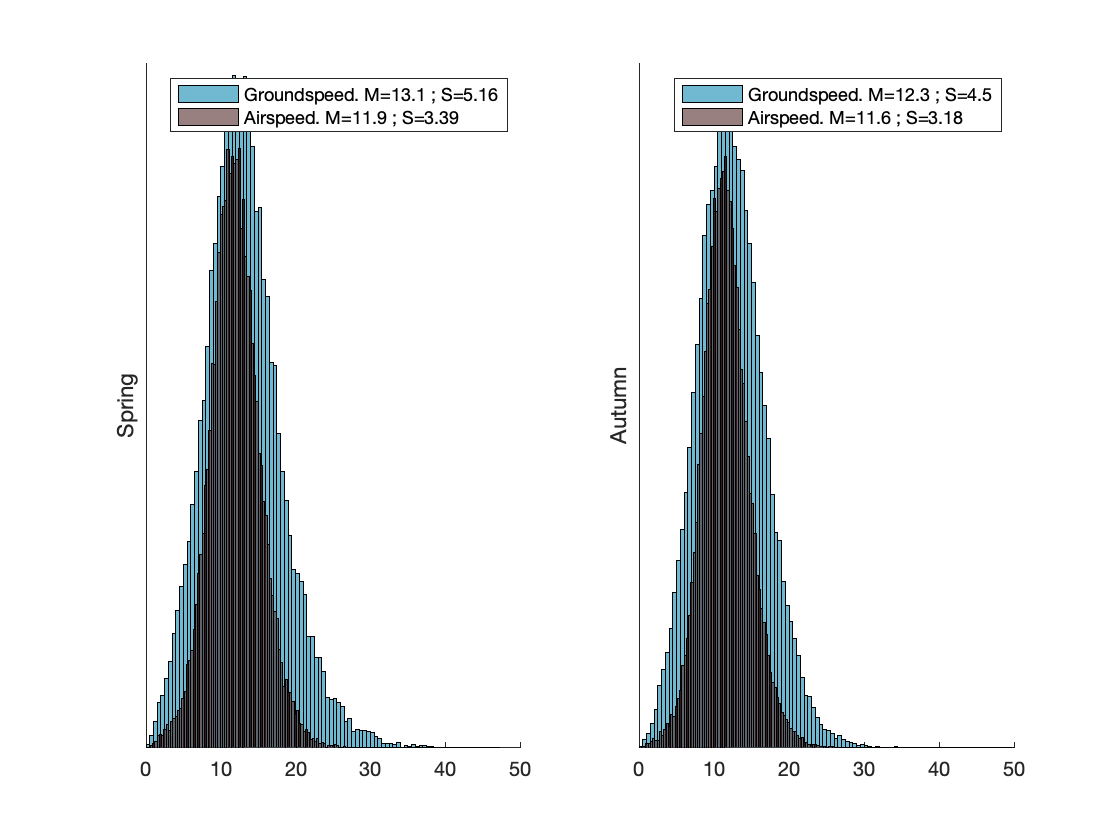

% yyaxis right;
% ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
% % subplot(3,1,3); 
% bar(t,mt,1,'k','FaceAlpha',0.2);
% legend('Daily airspeed','Daily groundspeed','7 days trend airspeed','7 days trend groundspeed','Wind profit','Orientation','horizontal','Location','northoutside');
% box on; ylim([-15 15]); grid on
% ylabel('Windspeed profit [m/s]')

#### Nilsson 2014

Ours Early-vs late migration

table({'March';'April';'Aug.-Sep.';'October';'Ratio short-distance';'Ratio long-distance'},[13.9;11.1;9.04;10.6;13.9/10.6;11.1/9.04],[9.18;8.22;7.55;8.85;9.18/8.85;8.22/7.55],'VariableNames',{'Season','Groundspeed','Airspeed'})

Nilsson 2014 Early-vs late migration (quite difference timing! based on riging at Falsterbo)

- 9/4 -> 24/4

- 25/4 -> 29/5

- 17/8 -> 9/9

- 9/9 -> 20/10

tmp_id_esp = T.time>datenum('9-April-2018') & T.time<datenum('24-April-2018');
tmp_id_lsp = T.time>datenum('9-April-2018') & T.time<datenum('24-April-2018');
tmp_id_au = T.time>datenum('25-July-2018') & T.time<datenum('31-August-2018');
[~,~,Mgsp,SDgsp] = histvdens(T.gs(tmp_id_sp),T.dens(tmp_id_sp));
[~,~,Mgau,SDgau] = histvdens(T.gs(tmp_id_au),T.dens(tmp_id_au));
[~,~,Masp,SDasp] = histvdens(T.as(tmp_id_sp),T.dens(tmp_id_sp));
[~,~,Maau,SDaau] = histvdens(T.as(tmp_id_au),T.dens(tmp_id_au));
table({'Ground speed' ;'Airspeed'},[Mgsp;Masp],[SDgsp;SDasp],[Mgau;Maau],[SDgau;SDaau],'VariableNames',{' ','Spring Mean','Spring SD','Autumn Mean','Autumn SD'})
table({'Spring-short dist';'Spring-long dist';'Autumn-long dist';'Atumn-short dist';'Ratio short-distance';'Ratio long-distance'},[14.56;12.7;8.77;13.69;14.56/13.69;12.7/8.77],[12.81;11.73;11.21;11.26;12.81/11.26;11.73/11.21],'VariableNames',{'Season','Groundspeed','Airspeed'})

### Over **night**

pplot = {'as','gs','ws','sd_vvp'};

ans = 6×3 table
             Season             Groundspeed    Airspeed
    ________________________    ___________    ________

    {'March'               }        13.9          9.18 
    {'April'               }        11.1          8.22 
    {'Aug.-Sep.'           }        9.04          7.55 
    {'October'             }        10.6          8.85 
    {'Ratio short-distance'}      1.3113        1.0373 
    {'Ratio long-distance' }      1.2279        1.0887 


x=-1:.01:1;
figure('position',[0 0 900 600]);
ha=tight_subplot(2,1,.01,[.09 0.09],[.08 0.01]); u=1;
for i_s=1:2
    axes(ha(u)); u=u+1; 
    clear h
    for i_p=1:numel(pplot)
%         tmp=nan(numel(dc_alt),ndc); tmp2=tmp; tmp3=tmp;
%         for i_d=1:ndc
%             id=T.r==i_d & id_s(:,i_s);

ans = 2×5 table
                        Spring Mean    Spring SD    Autumn Mean    Autumn SD
    ________________    ___________    _________    ___________    _________

    {'Ground speed'}      10.328        5.5756        8.7079        3.3124  
    {'Airspeed'    }      8.3158        3.1197        7.5099         2.537  


%             if sum(id)>0

ans = 6×3 table
             Season             Groundspeed    Airspeed
    ________________________    ___________    ________

    {'Spring-short dist'   }       14.56         12.81 
    {'Spring-long dist'    }        12.7         11.73 
    {'Autumn-long dist'    }        8.77         11.21 
    {'Atumn-short dist'    }       13.69         11.26 
    {'Ratio short-distance'}      1.0636        1.1377 
    {'Ratio long-distance' }      1.4481        1.0464 


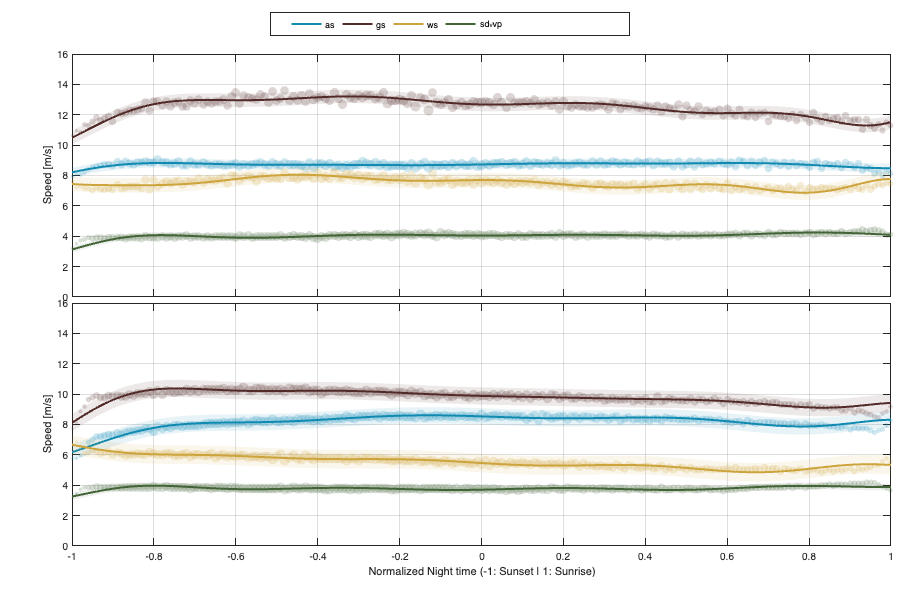

%                 [G,Galt]=findgroups(round(T.NNT(id),2));
%         
%                 tmp(1:numel(Galt),i_d) = splitapply(@sum,T.dens(id), G);
%                 tmp2(1:numel(Galt),i_d) = splitapply(@(x) sum(x(:,1).*x(:,2)./sum(x(:,2))), [T.(pplot{i_p})(id) T.dens(id)], G);
%                 tmp3(1:numel(Galt),i_d) = Galt;
%             end
%         end
%         s = (tmp(:)); s = 100*s./max(s); idd = ~isnan(s)&s~=0;
%         scatter(tmp3(idd),tmp2(idd),s(idd),colorder(i_p,:),'filled','MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
        
        id=id_s(:,i_s);
        if sum(id)>0
            [G,Galt]=findgroups(round(T.NNT(id),2));
            tmp = splitapply(@nansum,T.dens(id), G);
            tmp2 = splitapply(@(x) nansum(x(:,1).*x(:,2)./nansum(x(:,2))), [T.(pplot{i_p})(id) T.dens(id)], G);
            tmp3 = Galt;
        end
        s = (tmp(:)); s = 100*s./max(s); idd = ~isnan(s)&s~=0;
        scatter(tmp3(idd),tmp2(idd),s(idd),colorder(i_p,:),'filled','MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
        [p,S]=polyfit(tmp3(~isnan(tmp2)),tmp2(~isnan(tmp2)),15);
        [y,delta] = polyval(p,x,S);
        hold on;
        fill([x fliplr(x)],[y+delta fliplr(y-delta)],colorder(i_p,:),'FaceAlpha',0.1,'EdgeColor','none')
        h(i_p)=plot(x,y,'color',colorder(i_p,:),'LineWidth',2);
    end
    xlim([-1 1]); ylim([0 16]); box on;

    if i_s==2
        xlabel('Normalized Night time (-1: Sunset | 1: Sunrise)')
        legend(h,pplot,'Orientation','horizontal','position',[.3 .94 .4 .04])
    else
        xticklabels('')
    end
    ylabel('Speed [m/s]'); grid on;
end

We use the NNT which normalize the time between sunset and sunrise between -1 and 1. 

- Sd_vvp is stable throughout the night with an increase around sunrise probably because of the movement of local bird (not migration). Airspeed also decrease during the last to datapoint of the night, and should be used (contaminated by non-migratory bird). 

- Windspeed is relatively stable, with a slight increase int he middle of the night in spring and a slight reduction throughou the night in autumn

- Groundspeed follows the same trend than windspeed: slight increase during the middle of the night in spring and constant reduction in autumn

- Density follows the same trend. Note that it is on a diferent scale - right y-scale and thus can't be compare for magnitude. 

- Airspeed is the strange-on out, with a much more constant trend, relatively constent in spring. autumn, airspeed seems to increase in the middle of the night and decrease in the second part of the night. 

## Energy

### Air density

Aims is to build a function converting airspeed into energy, to do so, we need the air density on the same data format than the other variable (density, speed etc...)


$$\rho \;=\frac{p}{R_{\textrm{specific}} T}$$


We  assume a constant specific gas constant

R_specific = 287.058; % J/(kg·K)

Pressure is taken from the altitude of each bin with the [barometric formula](https://en.wikipedia.org/wiki/Barometric_formula)**.**

T_pressure = (1-T.alt*2.25577*10^(-5)).^(5.25588)*101325/100;

Air density is thus:

Tairdens = T_pressure*100 ./ Twt /R_specific; % hPa * Pa/hPa / K * kg*K/J = Pa*kg/J = kg/m^3

## Energy Calculation

In this section we define the energy power function, which provides the energy `eng` spent by a bird of mass `m`, wingspan `B` would spend flying at `vt` and with air density `airdens`. We also explore quickly the variation of optimal speed (i.e, lower energy) for different type of bird. 

Parameter for energy speding

k=1.2; % [-] Induced power factor (p. 45).
% m [kg] mass of bird.
gcst = 9.81; % [ms-2] gravity constant
% Vt [m/s] true speed (bird speed-wind speed)
% B [m] Wing span. 
% airdens = 1; % Air density 
Sb = @(m) 0.00813*m^0.666; % [m2] body frontal area
CDb = 0.1; % [-] body drag coefficient (p. 51).
Cpro = 8.4;
Ra = 7;

Define the function of energy

f_eng = @(Vt, airdens, m, B) (2*k*(m*gcst)^2)./(Vt*pi*B.^2.*airdens) + airdens.*Vt.^3*Sb(m)*CDb/2 + Cpro/Ra*1.05*k^(3/4)*m^(3/2)*gcst^(3/2)*Sb(m)^(1/4)*CDb^(1/4)./airdens.^(1/2)/B^(3/2);

Use data from appendix of Aurbach et al., (2020) for average mass and wingspan for migrant. 

Sp = table();
Sp.name = {'Willow Warbler'	'Tree Pipit'	'Common Chiffchaff'	'Spotted Flycatcher'	'Garden Warbler'	'Common Whitethroat'	'European Pied Flycatcher'	'Common Redstart'	'Wood Warbler'	'Eurasian Blackcap' 'Song Thrush'}';
Sp.massmin = [8 	20	6	13	16	12	9	12	7	14 83]';
Sp.massmax = [10	25	9	19	23	18	15	20	12	20 83]';
Sp.wingmin = [17	25	15	23	20	19	22	21	20	22 34]';
Sp.wingmax = [22	27	21	25	24	23	24	24	24	24 34]';
Sp.abondance = [27.5	12.7	11.3	8.7	7.3	7.1	6.8	6.6	6.1	5.9 nan]';

Compute average mass and wingspan

Sp.massmean = (Sp.massmin+Sp.massmax)/2/1000; % [kg]
Sp.wingmean = (Sp.wingmin+Sp.wingmax)/2/100; % [m]

Sort the table by mass

Sp=sortrows(Sp,'massmean')

Sp = 11×8 table
                name                massmin    massmax    wingmin    wingmax    abondance    massmean    wingmean
    ____________________________    _______    _______    _______    _______    _________    ________    ________

    {'Common Chiffchaff'       }       6          9         15         21         11.3        0.0075       0.18  
    {'Willow Warbler'          }       8         10         17         22         27.5         0.009      0.195  
    {'Wood Warbler'            }       7         12         20         24          6.1        0.0095       0.22  
    {'European Pied Flycatcher'}       9         15         22         24          6.8         0.012       0.23  
    {'Common Whitethroat'  

Compute the weighted average (accounting for abundance of each species

B_avg = nansum(Sp.wingmean.*Sp.abondance/100);
m_avg = nansum(Sp.massmean.*Sp.abondance/100);

Filter specie of interest

Sp=Sp([2 10 11],:);

**Energy as a function of species mass and wingspan**

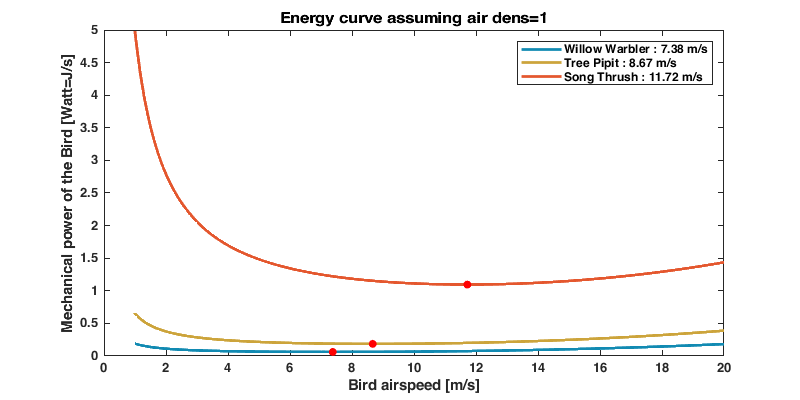

vt=1:0.01:20; 
p=nan(size(Sp,1),1);
figure('position',[0 0 800 400]); hold on; box on;
for i_s=1:size(Sp,1)
    Pvt = f_eng(vt, 1, Sp.massmean(i_s), Sp.wingmean(i_s));
    [~, tmp] = min(Pvt); 
    p(i_s)=plot(vt, Pvt,'LineWidth',2,'displayname',[Sp.name{i_s} ' : ' num2str(vt(tmp)) ,' m/s' ]);
    scatter(vt(tmp),min(Pvt),'or','filled')
end
legend(p); xlabel('Bird airspeed [m/s]'); ylabel('Mechanical power of the Bird [Watt=J/s]');
title('Energy curve assuming air dens=1')

The variation of optimal speed does not seem huge with these bird (7.2 - 8.4 m/s). But, we are  missing some bigger bird (e.g., thrush).

**Energy as a function of air density**

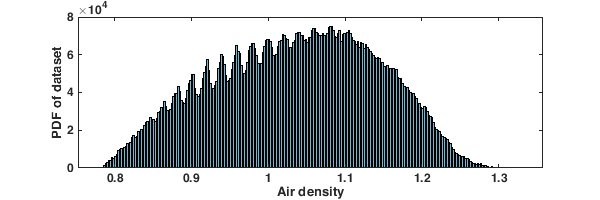

figure('position',[0 0 600 200]); histogram(Tairdens); xlabel('Air density'); ylabel('PDF of dataset')

Air density presents in the database.

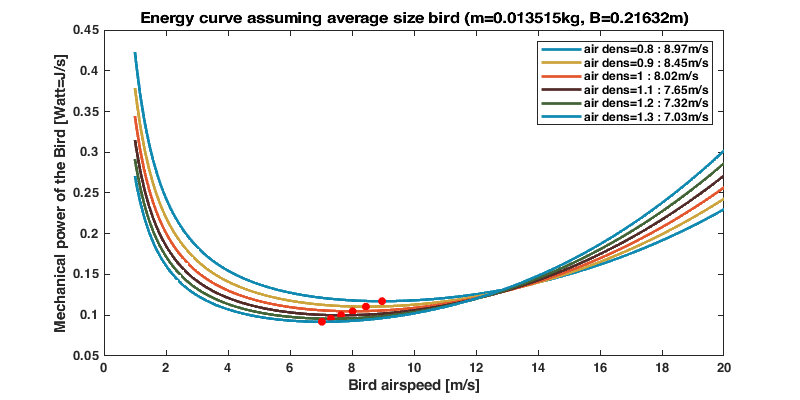

figure('position',[0 0 800 400]); hold on; box on;
ad = 0.8:0.1:1.3;
p=nan(size(ad));
for i_s = 1:numel(ad)
    Pvt = f_eng(vt,ad(i_s),m_avg,B_avg);
    [~, tmp] = min(Pvt); 
    p(i_s)=plot(vt, Pvt,'LineWidth',2,'displayname',['air dens=' num2str(ad(i_s)) ' : ' num2str(vt(tmp)) 'm/s']);
    scatter(vt(tmp),min(Pvt),'or','filled')
end
legend(p); xlabel('Bird airspeed [m/s]'); ylabel('Mechanical power of the Bird [Watt=J/s]');
title(['Energy curve assuming average size bird (m=' num2str(m_avg) 'kg, B=' num2str(B_avg) 'm)'])

Note that air density plays also a role in the optimale speed of bird, whithin the variation of the airdensity observed (computed from ERA dataset). 

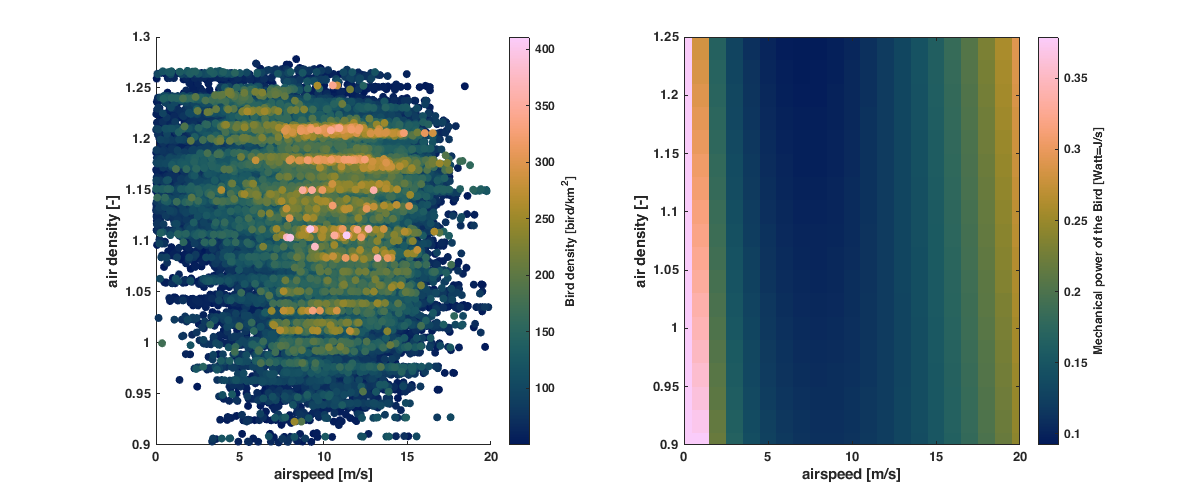

[V,A] = meshgrid(0:20,0.9:0.02:1.3);
E = f_eng(V, A, m_avg,B_avg);
lim = 50;
tmp = [T.as(T.dens>lim) Tairdens(T.dens>lim) T.dens(T.dens>lim)];
[~,idx] = sort(tmp(:,3)); % sort just the first column
tmp = tmp(idx,:);
figure('position',[0 0 1200 500]); 
subplot(1,2,1)
scatter(tmp(:,1),tmp(:,2),[],tmp(:,3),'filled')
xlabel('airspeed [m/s]'); ylabel('air density [-]'); 
c=colorbar; c.Label.String='Bird density [bird/km^2]'; 
xlim([0 20]); ylim([0.9 1.3]);
subplot(1,2,2);
imagesc(V(1,:),A(:,1),E); 
ax = gca; ax.YDir = 'normal';
xlim([0 20]); ylim([0.9 1.25]);
xlabel('airspeed [m/s]'); ylabel('air density [-]'); 
c=colorbar; c.Label.String='Mechanical power of the Bird [Watt=J/s]'; 

In this figure, I compare the airspeed/airdensity usage of bird with the optimal according to mechanical theory. Left subplot shows the actually usage (warmer color=more bird), and right panel shows the optimal for an average sized bird (colder cooler=more optimal). 

- Air density does not playa big role

- Bird should really not fly lower than 3m/s, yet we do observed some airspeed very low. 

- Generally, highest density are present with airspeed slightly higher than theory (9-12m/s vs 7-10 m/s).

Compute the energy for the entire dataset assuming an averaged size bird.

eng = f_eng(T.as, Tairdens, m_avg, B_avg);

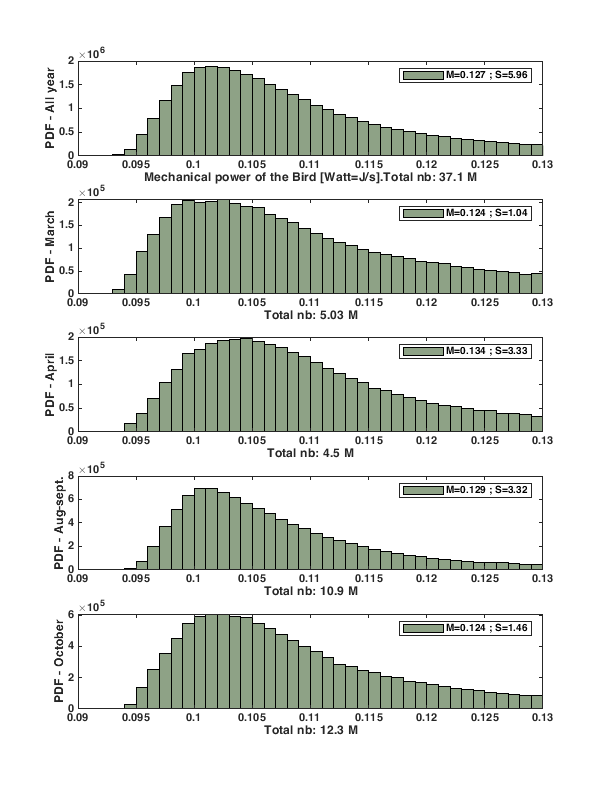

Error using subplot (line 319)
Index exceeds number of subplots.

figure('position',[0 0 600 800]);
subplot(5,1,1);
[b,h,Mg,Sg] = histvdens(eng, T.dens, 0.09:0.001:0.15);
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',colorder(4,:));xlim([0.09 0.13])
legend; xlabel(['Mechanical power of the Bird [Watt=J/s].Total nb: ' num2str(sum(T.dens)/1000000,3) ' M']); 
box on; ylabel('PDF - All year')
for i_s=3:size(id_s,1)
    subplot(5,1,i_s-1);
    [b,h,Mg,Sg] = histvdens(eng(id_s(:,i_s)), T.dens(id_s(:,i_s)),0.09:0.001:0.15);
    bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',colorder(4,:));xlim([0.09 0.13])
    legend; xlabel(['Total nb: ' num2str(sum(T.dens(id_s(:,i_s)))/1000000,3) ' M']); 
    box on; ylabel(['PDF - ' id_s_name{i_s}])
end

Distribution of the energy spend by bird for various period of the year. We account for the density of bird (i.e., how many bird are spending this energy). But we do not account for change of mass. 